# Project: MIMO Simulation at 28 GHz in an Indoor Environment

### Github :    https://github.com/salmane-s9/wireless_project

## Loading the Data

We first load the data with a structure `pathData `containing Ray Tracing results in an indoor environment with a single TX (`pathData.txPos`) and a large number of RX locations (`pathData.rxPos)`. 

Each RX location i has an associated number of valid paths (`pathData.npaths(i)`) and a description of the link state (`pathData.linkState(i)`) {'LOS', 'NLOS', 'Outage'}. 

We dispose also the of the corresponding path losses, AoA and AoD of the individual paths.

% Loading the data from the Github repository
load roomPathData.mat;
txPos = pathData.txPos;
nrxPos = size(pathData.rxPos, 1);
fprintf(1, 'Tx Position  = [%.2f, %.2f]\n', txPos(1), txPos(2));

Tx Position  = [7.30, -9.30]


fprintf(1, 'Number of Rx locations = %d\n', nrxPos);

Number of Rx locations = 5071


## Selecting a RX location

We use the DataMapper object to visualize the environment and the corresponding values for each RX location. Initially, we randomly select an RX Location with a Line of Sight (LOS) connection and proceed with further analysis using that location.

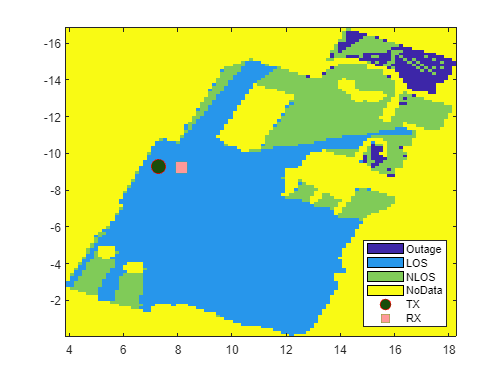

% To start with, we select a location with linkState = LOS

% We instanciate the Mapper Object
rxPos = pathData.rxPos;
mapper = DataMapper(rxPos, pathData.posStep);

% We randomly choose a position;
idx_rx = randsample(find(pathData.linkState==1), 1);
rxPos1 = rxPos(idx_rx,:);

clf;
noDataValue = 3;  % Use this value for positions with no data

legendLabels = {'Outage', 'LOS', 'NLOS', 'NoData'};

mapper.plot(pathData.linkState, 'noDataValue', noDataValue, ...
    'LegendLabels', legendLabels, 'plotHold',true);
txPos = pathData.txPos;
plot(txPos(1), txPos(2), 'ro', 'MarkerSize', 12, 'MarkerFaceColor',[0.1 0.3 0.04], 'DisplayName', 'TX');
hold on;

% Overlay the Rx position
txPos = pathData.txPos;
plot(rxPos1(1), rxPos1(2), 's', 'MarkerSize', 12, 'MarkerFaceColor',[1 .6 .6], 'DisplayName', 'RX');
hold off;

% Display the legend
legend('Location', 'SouthEast');

## Creating the Array Platforms

We next construct the arrays at the Tx and Rx. Use a lambda / 2 separation. As in the slides, we consruct a 4*4 URA at the TX and a 8 antennas ULA at the RX.

We use as well the ArrayPlatform class to help to the array structure and compute the normalizaton matrix and normalized steering vectors in a given set of angles.

% Creating the Antenna Arrays on both the TX and RX. 
fc = pathData.fc;
fprintf(1, 'Carrier Frequency = %.1f GHz\n', pathData.fc*1e-9)

Carrier Frequency = 28.0 GHz


elem = design(patchMicrostrip, fc);
elem.Tilt = 90;
elem.TiltAxis =[0,1,0];

% Number of antennas 
nantTx = [4,4];              % Number of TX elements
nantRx = 8;                  % Number of RX elements

% Constructing a URA

sep = 0.5*(physconst('Lightspeed')/fc);
arrTx = phased.URA(nantTx, sep);
arrRx = phased.ULA(nantRx, sep);

% Creating the Array Platform

arrPlatformTx = ArrayPlatform('elem', elem, 'arr', arrTx, 'fc', fc);
arrPlatformTx.computeNormMatrix();

arrPlatformRx =  ArrayPlatform('elem', elem, 'arr', arrRx, 'fc', fc);
arrPlatformRx.computeNormMatrix();

We will now compute the gains on a multi-path channel. We use the 3GPP CDL-C model. The path

parameters can be obtianed in MATLAB as follows.

% Channel Parameters from the pathDATA file

pl_rx = pathData.pl(idx_rx,:)';
dly_rx = pathData.dly(idx_rx,:)';
gain_rx = pathData.gain(idx_rx,:)';
aoaAz = pathData.aoaAz(idx_rx,:)';
aoaEl = pathData.aoaEl(idx_rx,:)';
aodAz = pathData.aodAz(idx_rx,:)';
aodEl = pathData.aodEl(idx_rx,:)';

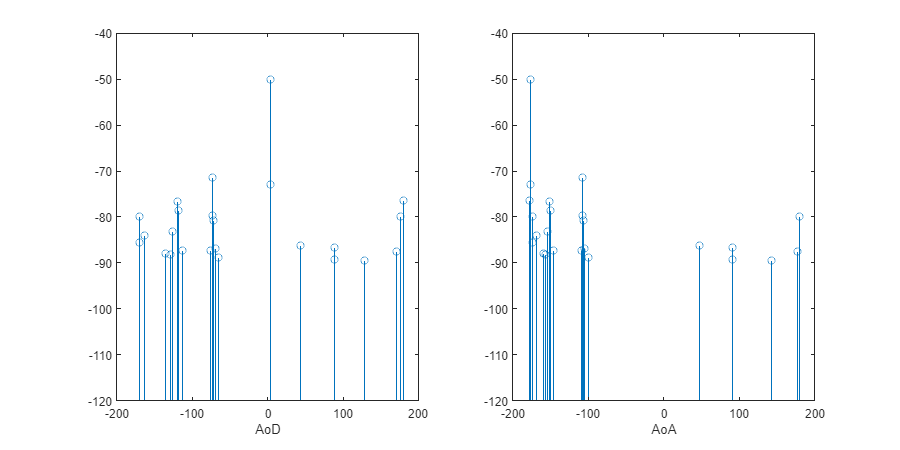

clf;
set(gcf,'Position', [0,0,1000,500]);
subplot(1, 2, 1);
stem(aodAz, gain_rx, 'BaseValue',-120);
xlabel('AoD');
subplot(1, 2, 2);
stem(aoaAz, gain_rx, 'BaseValue',-120);
xlabel('AoA');

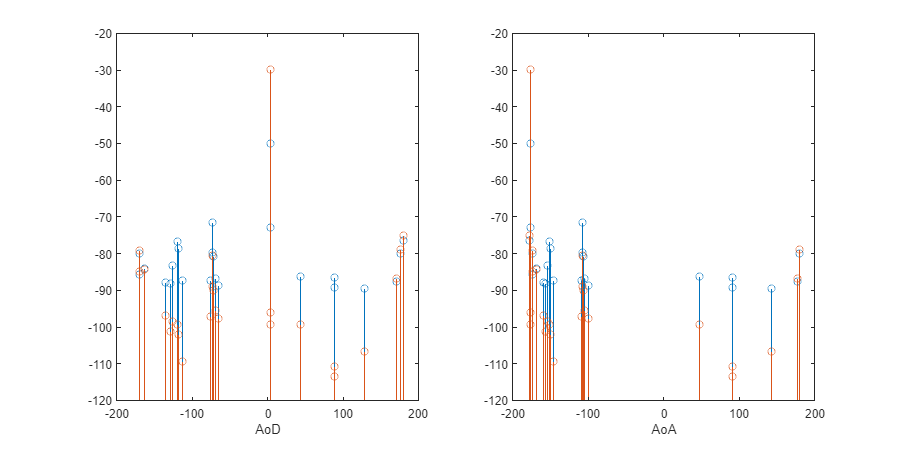

% Rotating the Rx  to the the main angle of arrival
[~,imax] = max(gain_rx);
azRx = aoaAz(imax);
elRx = aoaEl(imax);
arrPlatformRx.alignAxes(azRx, elRx);

% Getting the element gains and steering vectors for both Tx and Rx
% elements

[svTx, elemGainTx] = arrPlatformTx.step(aodAz, aodEl);
[svRx, elemGainRx] = arrPlatformRx.step(aoaAz, aoaEl);

gainElem = gain_rx + elemGainTx + elemGainRx;

clf;
set(gcf,'Position', [0,0,1000,500]);
subplot(1, 2, 1);
stem(aodAz, [gain_rx gainElem], 'BaseValue',-120);
xlabel('AoD');
subplot(1, 2, 2);
stem(aoaAz, [gain_rx gainElem], 'BaseValue',-120);
xlabel('AoA');

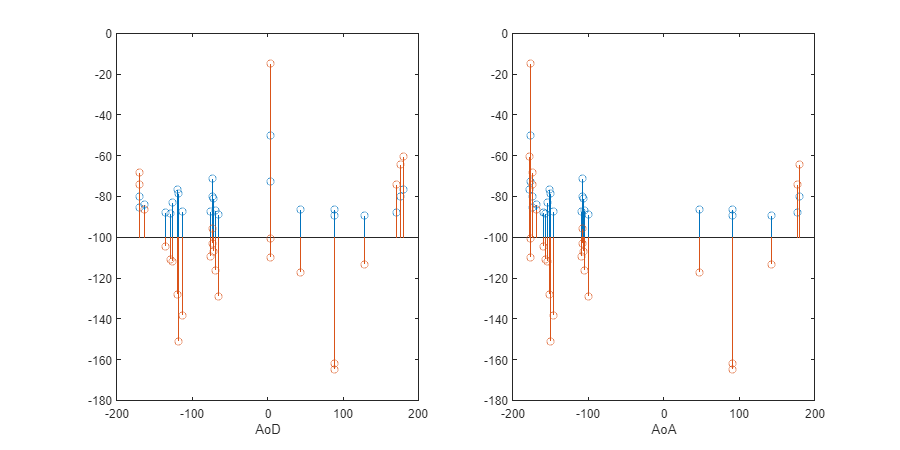

% Computing the gain Array 

[~,imax] = max(gainElem);
wtx = conj(svTx(:, imax));
wtx = wtx / norm(wtx);
wrx = conj(svRx(:, imax));
wrx = wrx / norm(wrx);

gainArr = gain_rx + mag2db(abs(wtx.'*svTx))' + mag2db(abs(wrx.'*svRx))';

clf;
set(gcf,'Position', [0,0,1000,500]);
subplot(1, 2, 1);
stem(aodAz, [gain_rx gainArr], 'BaseValue',-100);
xlabel('AoD');
subplot(1, 2, 2);
stem(aoaAz, [gain_rx gainArr], 'BaseValue',-100);
xlabel('AoA');

## Visualizing the MIMO OFDM Channel

Next, We visualize the OFDM channel with and without the beamforming  we use the carrierConfig and waveformConfig similarly to what we did in the previous labs.

% We simulate the Frequency Domain Channel with and without Beamforming
SubcarrierSpacing = 120; % SCS in kHZ
NRB = 61; % number of resource blocks
nscPerRB = 12; % number of sub-carriers per RB

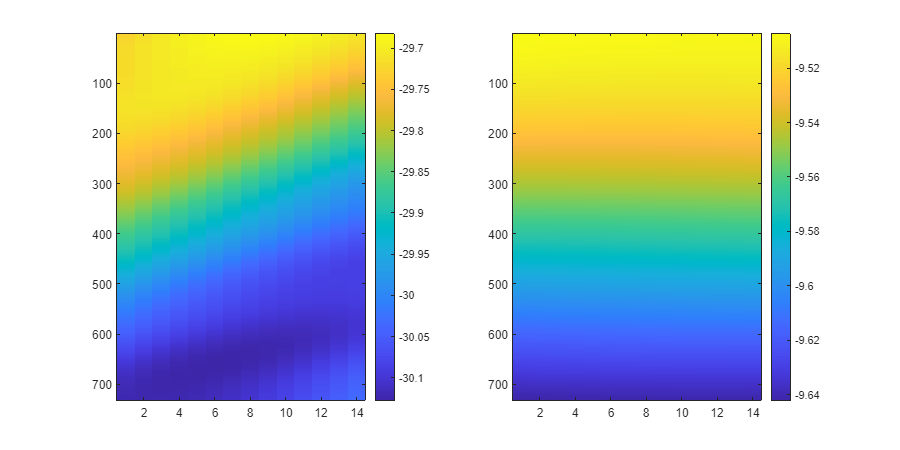

% we get the carrierConfig and waveformConfig with the nrCarrierConfig and
% nrOFDMInfo methods in the 5G Toolbox.

carrierConfig = nrCarrierConfig( ...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);

Enoise = -5; % Energy per noise sample in dB
Etx = 1; % Average transmitted symbol energy
snrAvg = 20; % Average SNR

fdchan = FDMIMOChan( ...
    carrierConfig, 'txArrPlatform', arrPlatformTx, 'rxArrPlatform', arrPlatformRx, ...
    'aoaAz', aoaAz, 'aodAz', aodAz, 'aoaEl', aoaEl, 'aodEl', aodEl, ...
    'gain', gain_rx, 'dly', dly_rx, 'fc', fc, 'Enoise', Enoise);

frameNum = 0;
slotNum = 0;
[chanGrid, noiseVar] = fdchan.step(frameNum, slotNum);

snrSing = pow2db(squeeze(abs(chanGrid(1,2,:,:)).^2) / noiseVar);

nsc = size(chanGrid, 3);
nsym = size(chanGrid, 4);

snrInst = zeros(nsc,nsym);
for i_sc=1:nsc
    for i_sym=1:nsym
        [~, svi, ~] = svds(squeeze(chanGrid(:,:,i_sc,i_sym)), 1);
        snrInst(i_sc,i_sym) = pow2db((svi)^2/noiseVar);
    end
end

% To check what is plotted (Which TX-Rx Pair)
clf;
set(gcf,'Position', [0,0,1000,500]);
subplot(1, 2, 1);
imagesc(snrSing);
colorbar();
subplot(1, 2, 2);
imagesc(snrInst);
colorbar();

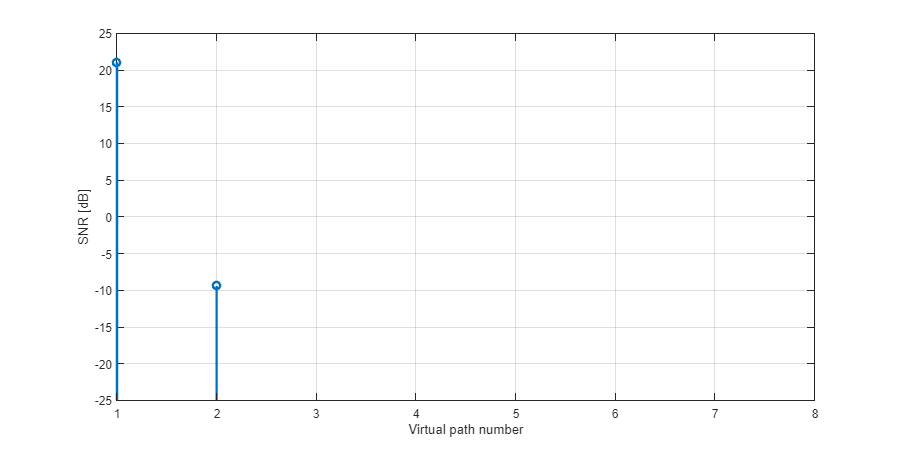

% We compute the channel matrix at a specific symbol and sub-carrier (1, 1)
nrx = arrPlatformRx.getNumElements();
ntx = arrPlatformTx.getNumElements();

H = chanGrid(:,:,4,3);
% Normalizing the Channel to get SNR per antenna
H = sqrt(nrx*ntx)*H / norm(H, 'fro');

% Get the SVD
[U,S,V] = svd(H,'econ');
s = diag(S);

% Eigenvalues
lam = s.^2;
clf;
% Plot the eigenvalues.
stem(pow2db(lam), 'BaseValue', -40, 'LineWidth', 2);
xlabel('Virtual path number');
ylabel('SNR [dB]');
grid on;
ylim([-25, 25]);

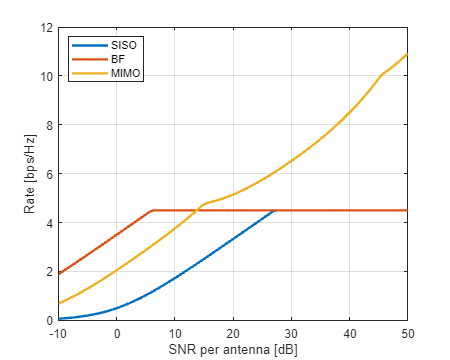

% SNR per antenna to test
snrTest = linspace(-10,50,100)';
nsnr = length(snrTest);

% Rate model parameters
bwScale = 0.5;
maxSE = 4.5;

% SISO rate
rateSISO = min(maxSE, bwScale*log2(1+ db2pow(snrTest)));

% MIMO rate with uniform power
rmax = length(s);
rateStream = min(maxSE, bwScale*log2(1+ db2pow(snrTest)*lam'/rmax));
rateMIMO = sum(rateStream, 2);

% BF rate with power allocated to top virtual path
rateBF = min(maxSE, bwScale*log2(1+ db2pow(snrTest)*lam(1)));

% Plot
clf;
set(gcf,'Position', [0,0,500,400]);
plot(snrTest, [rateSISO rateBF rateMIMO], 'Linewidth', 2);
grid on;
xlabel('SNR per antenna [dB]');
ylabel('Rate [bps/Hz]');
legend('SISO', 'BF', 'MIMO', 'Location', 'Northwest');

## Simulate a DL PDSCH throughput 

In this section, we measure the PDSCH throughput of a 5G-NR link. The link example is taken from [https://www.mathworks.com/help/5g/ug/nr-pdsch-throughput.html](https://www.mathworks.com/help/5g/ug/nr-pdsch-throughput.html)  and implements the PDSCH and downlink shared channel. The simulation was adapted to consider the Ray Tracing data produced from the indoor environment.

Like the previous labs, we obtain the carrier configuration and waveform configuration using the `nrCarrierConfig` and `nrOFDMInfo` methods in the 5G Toolbox. The simulation we are conducting is designed to support DL-SCH transport channel coding, including the generation of PDSCH, PDSCH DM-RS, and PDSCH PT-RS. It incorporates various features such as:

- PDSCH subband precoding using SVD

- CP-OFDM modulation

- PDSCH and DM-RS mapping per slot

- Channel estimation

- multiple HARQ processes

We can use the previously defined FDMIMO channel object for simulation. However, we opted to utilize a clustered delay line (CDL) model with parameters obtained from the indoor environment for better compatibility with the simulation. In the initial phase, we assume no channel estimation and run the simulation with complete knowledge of the channel. Subsequently, we compare the throughput results between perfect channel knowledge and practical channel estimation based on the received PDSCH DM-RS.

**The steps of the simulation are as follows: **

- The 5G NR DM-RS and PT-RS have predefined parameters, and HARQ is pre-configured with a set number of processes. Additionally, an LDPC Decoding Algorithm is initialized for channel decoding.

- After configuration, first thing is to update the HARQ process by checking the transmission status for the current one and generating new data

- Generate the ressource grid by determining the PT-RS and DM-RS symbols and add them to the TX grid and modulating the coded bits ( A internal copy of the total transport block is kept in case of a retransmission)

- Precoding using SVD ( An initial Precoding assumes perfect knowledge of the channel)

- Then, the waveform is generated and passed through the noisy channel defined from the indoor environment for the corresponding TX-RX pair (We use CDL-C channel models with parameters from the environment as it is compatible witrh the simulation. 

- Next, Synchronization and OFDM demodulation are performed. We first assume perfect knowledge of the channel which make it perform well. But later for practical settings, synchronization is done by correlating the received waveform with the DM-RS and then OFDM demodulate the synchronized signal.

- After we perform channel estimation (either by using the exact Channel Grid or by practical channel estimation using the PDSCH DM-RS.

- We use after LMMSE to equalize the estimated channel and similarly with the common phase error using the PT-RS symbols. 

- Subsequently, we generate the next precoding matrix W for the next transmission.

- Finally, we decode the PDSCH abd the DL-SCH to recover all the PDSCH symbols with update the HARQ process using the block CRC error which helps determining the throughput of the system.

   Only 2 Frames are transmitted but it would be better to run with a higher number for approriate results.

simParameters = struct();       % Clear simParameters variable to contain all key simulation parameters
simParameters.NFrames = 2;      % Number of 10 ms frames
% simParameters.SNRIn = [-20 -10]; % SNR range (dB)
simParameters.SNRIn = (-18:2:16); % SNR range (dB)
simParameters.nscPerRB = 12;  % number of sub-carriers per RB
simParameters.PerfectChannelEstimator = true;
simParameters.DisplaySimulationInformation = true;
simParameters.DisplayDiagnostics = false;

% Set waveform type and PDSCH numerology (SCS and CP type)

simParameters.Carrier = nrCarrierConfig( ...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing, ...
    'CyclicPrefix','normal', 'NCellID',1);

simParameters.waveformConfig =  nrOFDMInfo(simParameters.Carrier);

% PDSCH/DL-SCH parameters
simParameters.PDSCH = nrPDSCHConfig;      % This PDSCH definition is the basis for all PDSCH transmissions in the BLER simulation
simParameters.PDSCHExtension = struct();  % This structure is to hold additional simulation parameters for the DL-SCH and PDSCH

% Define PDSCH time-frequency resource allocation per slot to be full grid (single full grid BWP)
simParameters.PDSCH.PRBSet = (0:simParameters.Carrier.NSizeGrid-1);                 % PDSCH PRB allocation
simParameters.PDSCH.SymbolAllocation = [0,simParameters.Carrier.SymbolsPerSlot];  % Starting symbol and number of symbols of each PDSCH allocation
simParameters.PDSCH.MappingType = 'A';     % PDSCH mapping type ('A'(slot-wise),'B'(non slot-wise))

% Scrambling identifiers
simParameters.PDSCH.NID = simParameters.Carrier.NCellID;
simParameters.PDSCH.RNTI = 1;

% PDSCH resource block mapping (TS 38.211 Section 7.3.1.6)
simParameters.PDSCH.VRBToPRBInterleaving = 0; % Disable interleaved resource mapping
simParameters.PDSCH.VRBBundleSize = 4;

% Define the number of transmission layers to be used
simParameters.PDSCH.NumLayers = 2;            % Number of PDSCH transmission layers

% Define codeword modulation and target coding rate
% The number of codewords is directly dependent on the number of layers so ensure that
% layers are set first before getting the codeword number
if simParameters.PDSCH.NumCodewords > 1                             % Multicodeword transmission (when number of layers being > 4)
    simParameters.PDSCH.Modulation = {'16QAM','16QAM'};             % 'QPSK', '16QAM', '64QAM', '256QAM'
    simParameters.PDSCHExtension.TargetCodeRate = [490 490]/1024;   % Code rate used to calculate transport block sizes
else
    simParameters.PDSCH.Modulation = '16QAM';                       % 'QPSK', '16QAM', '64QAM', '256QAM'
    simParameters.PDSCHExtension.TargetCodeRate = 490/1024;         % Code rate used to calculate transport block sizes
end

% DM-RS and antenna port configuration (TS 38.211 Section 7.4.1.1)
simParameters.PDSCH.DMRS.DMRSPortSet = 0:simParameters.PDSCH.NumLayers-1; % DM-RS ports to use for the layers
simParameters.PDSCH.DMRS.DMRSTypeAPosition = 2;      % Mapping type A only. First DM-RS symbol position (2,3)
simParameters.PDSCH.DMRS.DMRSLength = 1;             % Number of front-loaded DM-RS symbols (1(single symbol),2(double symbol))
simParameters.PDSCH.DMRS.DMRSAdditionalPosition = 2; % Additional DM-RS symbol positions (max range 0...3)
simParameters.PDSCH.DMRS.DMRSConfigurationType = 2;  % DM-RS configuration type (1,2)
simParameters.PDSCH.DMRS.NumCDMGroupsWithoutData = 1;% Number of CDM groups without data
simParameters.PDSCH.DMRS.NIDNSCID = 1;               % Scrambling identity (0...65535)
simParameters.PDSCH.DMRS.NSCID = 0;                  % Scrambling initialization (0,1)

% PT-RS configuration (TS 38.211 Section 7.4.1.2)
simParameters.PDSCH.EnablePTRS = 0;                  % Enable or disable PT-RS (1 or 0)
simParameters.PDSCH.PTRS.TimeDensity = 1;            % PT-RS time density (L_PT-RS) (1, 2, 4)
simParameters.PDSCH.PTRS.FrequencyDensity = 2;       % PT-RS frequency density (K_PT-RS) (2 or 4)
simParameters.PDSCH.PTRS.REOffset = '00';            % PT-RS resource element offset ('00', '01', '10', '11')
simParameters.PDSCH.PTRS.PTRSPortSet = [];           % PT-RS antenna port, subset of DM-RS port set. Empty corresponds to lower DM-RS port number

% Reserved PRB patterns, if required (for CORESETs, forward compatibility etc)
simParameters.PDSCH.ReservedPRB{1}.SymbolSet = [];   % Reserved PDSCH symbols
simParameters.PDSCH.ReservedPRB{1}.PRBSet = [];      % Reserved PDSCH PRBs
simParameters.PDSCH.ReservedPRB{1}.Period = [];      % Periodicity of reserved resources
 
% Additional simulation and DL-SCH related parameters

% PDSCH PRB bundling (TS 38.214 Section 5.1.2.3)
simParameters.PDSCHExtension.PRGBundleSize = [];     % 2, 4, or [] to signify "wideband"

% HARQ process and rate matching/TBS parameters
simParameters.PDSCHExtension.XOverhead = 6*simParameters.PDSCH.EnablePTRS; % Set PDSCH rate matching overhead for TBS (Xoh) to 6 when PT-RS is enabled, otherwise 0
simParameters.PDSCHExtension.NHARQProcesses = 16;    % Number of parallel HARQ processes to use
simParameters.PDSCHExtension.EnableHARQ = true;      % Enable retransmissions for each process, using RV sequence [0,2,3,1]

% LDPC decoder parameters
% Available algorithms: 'Belief propagation', 'Layered belief propagation', 'Normalized min-sum', 'Offset min-sum'
simParameters.PDSCHExtension.LDPCDecodingAlgorithm = 'Normalized min-sum';
simParameters.PDSCHExtension.MaximumLDPCIterationCount = 6;

% Define the overall transmission antenna geometry at end-points
% If using a CDL propagation channel then the integer number of antenna elements is
% turned into an antenna panel configured when the channel model object is created
simParameters.NTxAnts = arrPlatformTx.getNumElements();
simParameters.NRxAnts = arrPlatformRx.getNumElements();

% Define the general CDL/TDL propagation channel parameters
simParameters.DelayProfile = 'Custom';   % Use CDL-C model (Urban macrocell model)

% Cross-check the PDSCH layering against the channel geometry
validateNumLayers(simParameters);
% The simulation relies on various pieces of information about the baseband waveform, such as sample rate.

waveformInfo = nrOFDMInfo(simParameters.Carrier); % Get information about the baseband waveform after OFDM modulation step
% Propagation Channel Model Construction
% Create the channel model object for the simulation. Both CDL and TDL channel models are supported [ 5 ].

% CDL channel object
channel = nrCDLChannel('DelayProfile','Custom', 'PathDelays',dly_rx', 'AveragePathGains',gain_rx', ...
    'AnglesAoA',aoaAz', 'AnglesAoD',aodAz', 'AnglesZoA',90-aoaEl', 'AnglesZoD',90-aodEl', ...
    'HasLOSCluster',true, 'CarrierFrequency', fc, 'SampleRate', waveformInfo.SampleRate, ...
    'TransmitAntennaArray',arrTx, 'ReceiveAntennaArray', arrRx);

chInfo = info(channel);
maxChDelay = chInfo.MaximumChannelDelay;

% Array to store the maximum throughput for all SNR points
maxThroughput = zeros(length(simParameters.SNRIn),1);
% Array to store the simulation throughput for all SNR points
simThroughput = zeros(length(simParameters.SNRIn),1);

% Set up redundancy version (RV) sequence for all HARQ processes
if simParameters.PDSCHExtension.EnableHARQ
    rvSeq = [0 2 3 1];
else
    % HARQ disabled - single transmission with RV=0, no retransmissions
    rvSeq = 0;
end

% Create DL-SCH encoder system object to perform transport channel encoding
encodeDLSCH = nrDLSCH;
encodeDLSCH.MultipleHARQProcesses = true;
encodeDLSCH.TargetCodeRate = simParameters.PDSCHExtension.TargetCodeRate;

% Create DL-SCH decoder system object to perform transport channel decoding
% Use layered belief propagation for LDPC decoding, with half the number of
% iterations as compared to the default for belief propagation decoding
decodeDLSCH = nrDLSCHDecoder;
decodeDLSCH.MultipleHARQProcesses = true;
decodeDLSCH.TargetCodeRate = simParameters.PDSCHExtension.TargetCodeRate;
decodeDLSCH.LDPCDecodingAlgorithm = simParameters.PDSCHExtension.LDPCDecodingAlgorithm;
decodeDLSCH.MaximumLDPCIterationCount = simParameters.PDSCHExtension.MaximumLDPCIterationCount;

for snrIdx = 1:numel(simParameters.SNRIn)      % comment out for parallel computing
% parfor snrIdx = 1:numel(simParameters.SNRIn) % uncomment for parallel computing
% To reduce the total simulation time, you can execute this loop in
% parallel by using the Parallel Computing Toolbox. Comment out the 'for'
% statement and uncomment the 'parfor' statement. If the Parallel Computing
% Toolbox is not installed, 'parfor' defaults to normal 'for' statement.
% Because parfor-loop iterations are executed in parallel in a
% nondeterministic order, the simulation information displayed for each SNR
% point can be intertwined. To switch off simulation information display,
% set the 'displaySimulationInformation' variable above to false

    % Reset the random number generator so that each SNR point will
    % experience the same noise realization
    rng('default');
    % Take full copies of the simulation-level parameter structures so that they are not
    % PCT broadcast variables when using parfor
    simLocal = simParameters;
    waveinfoLocal = waveformInfo;

    % Take copies of channel-level parameters to simplify subsequent parameter referencing
    carrier = simLocal.Carrier;
    pdsch = simLocal.PDSCH;
    pdschextra = simLocal.PDSCHExtension;
    decodeDLSCHLocal = decodeDLSCH;  % Copy of the decoder handle to help PCT classification of variable
    decodeDLSCHLocal.reset();        % Reset decoder at the start of each SNR point
    pathFilters = [];

    % Prepare simulation for new SNR point
    SNRdB = simLocal.SNRIn(snrIdx);
    fprintf('\nSimulating transmission scheme 1 (%dx%d) and SCS=%dkHz with channel at %gdB SNR for %d 10ms frame(s)\n', ...
        simLocal.NTxAnts,simLocal.NRxAnts,carrier.SubcarrierSpacing,SNRdB,simLocal.NFrames);

    % Specify the fixed order in which we cycle through the HARQ process IDs
    harqSequence = 0:pdschextra.NHARQProcesses-1;

    % Initialize the state of all HARQ processes
    harqEntity = HARQEntity(harqSequence,rvSeq,pdsch.NumCodewords);

    % Reset the channel so that each SNR point will experience the same
    % channel realization
    reset(channel);
    
    % Total number of slots in the simulation period
    NSlots = simLocal.NFrames * carrier.SlotsPerFrame;

    % Obtain a precoding matrix (wtx) to be used in the transmission of the
    % first transport block
    estChannelGrid = getInitialChannelEstimate(carrier,simLocal.NTxAnts,channel);    
    newWtx = getPrecodingMatrix(carrier,pdsch,estChannelGrid,pdschextra.PRGBundleSize);
    
    % Timing offset, updated in every slot for perfect synchronization and
    % when the correlation is strong for practical synchronization
    offset = 0;

    % Loop over the entire waveform length
    for nslot = 0:NSlots-1

        % Update the carrier slot numbers for new slot
        carrier.NSlot = nslot;

        % Calculate the transport block sizes for the transmission in the slot
        [pdschIndices,pdschIndicesInfo] = nrPDSCHIndices(carrier,pdsch);
        trBlkSizes = nrTBS(pdsch.Modulation,pdsch.NumLayers,numel(pdsch.PRBSet),pdschIndicesInfo.NREPerPRB,pdschextra.TargetCodeRate,pdschextra.XOverhead);
        
        % HARQ processing
        for cwIdx = 1:pdsch.NumCodewords
            % If new data for current process and codeword then create a new DL-SCH transport block
            if harqEntity.NewData(cwIdx)
                trBlk = randi([0 1],trBlkSizes(cwIdx),1);
                setTransportBlock(encodeDLSCH,trBlk,cwIdx-1,harqEntity.HARQProcessID);
                % If new data because of previous RV sequence time out then flush decoder soft buffer explicitly
                if harqEntity.SequenceTimeout(cwIdx)
                    resetSoftBuffer(decodeDLSCHLocal,cwIdx-1,harqEntity.HARQProcessID);
                end
            end
        end

        % Encode the DL-SCH transport blocks
        codedTrBlocks = encodeDLSCH(pdsch.Modulation,pdsch.NumLayers, ...
            pdschIndicesInfo.G,harqEntity.RedundancyVersion,harqEntity.HARQProcessID);
        
        % Get precoding matrix (wtx) calculated in previous slot
        wtx = newWtx;
        
        % Create resource grid for a slot
        pdschGrid = nrResourceGrid(carrier,simLocal.NTxAnts);

        % PDSCH modulation and precoding
        pdschSymbols = nrPDSCH(carrier,pdsch,codedTrBlocks);
        [pdschAntSymbols,pdschAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,pdschSymbols,pdschIndices,wtx);

        % PDSCH mapping in grid associated with PDSCH transmission period
        pdschGrid(pdschAntIndices) = pdschAntSymbols;

        % PDSCH DM-RS precoding and mapping
        dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
        dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);
        [dmrsAntSymbols,dmrsAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,dmrsSymbols,dmrsIndices,wtx);
        pdschGrid(dmrsAntIndices) = dmrsAntSymbols;

        % PDSCH PT-RS precoding and mapping
        ptrsSymbols = nrPDSCHPTRS(carrier,pdsch);
        ptrsIndices = nrPDSCHPTRSIndices(carrier,pdsch);
        [ptrsAntSymbols,ptrsAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,ptrsSymbols,ptrsIndices,wtx);
        pdschGrid(ptrsAntIndices) = ptrsAntSymbols;

        % OFDM modulation
        
        txWaveform = nrOFDMModulate(carrier,pdschGrid);
        % Pass data through channel model. Append zeros at the end of the
        % transmitted waveform to flush channel content. These zeros take
        % into account any delay introduced in the channel. This is a mix
        % of multipath delay and implementation delay. This value may
        % change depending on the sampling rate, delay profile and delay
        % spread
        txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))]; %#ok<AGROW>
        [rxWaveform,pathGains,sampleTimes] = channel(txWaveform);
        

        % Add AWGN to the received time domain waveform
        % Normalize noise power by the IFFT size used in OFDM modulation,
        % as the OFDM modulator applies this normalization to the
        % transmitted waveform. Also normalize by the number of receive
        % antennas, as the channel model applies this normalization to the
        % received waveform, by default
        SNR = 10^(SNRdB/10);
        N0 = 1/sqrt(2.0*simLocal.NRxAnts*double(waveinfoLocal.Nfft)*SNR);
        noise = N0*complex(randn(size(rxWaveform)),randn(size(rxWaveform)));
        rxWaveform = rxWaveform + noise;
        
        if (simLocal.PerfectChannelEstimator)
            % Perfect synchronization. Use information provided by the
            % channel to find the strongest multipath component
            pathFilters = getPathFilters(channel);
            [offset,mag] = nrPerfectTimingEstimate(pathGains,pathFilters);
        else
            % Practical synchronization. Correlate the received waveform
            % with the PDSCH DM-RS to give timing offset estimate 't' and
            % correlation magnitude 'mag'. The function
            % hSkipWeakTimingOffset is used to update the receiver timing
            % offset. If the correlation peak in 'mag' is weak, the current
            % timing estimate 't' is ignored and the previous estimate
            % 'offset' is used
            [t,mag] = nrTimingEstimate(carrier,rxWaveform,dmrsIndices,dmrsSymbols);
            offset = hSkipWeakTimingOffset(offset,t,mag);
            % Display a warning if the estimated timing offset exceeds the
            % maximum channel delay
            if offset > maxChDelay
                warning(['Estimated timing offset (%d) is greater than the maximum channel delay (%d).' ...
                    ' This will result in a decoding failure. This may be caused by low SNR,' ...
                    ' or not enough DM-RS symbols to synchronize successfully.'],offset,maxChDelay);
            end
        end
        rxWaveform = rxWaveform(1+offset:end,:);
        
        % Perform OFDM demodulation on the received data to recreate the
        % resource grid, including padding in the event that practical
        % synchronization results in an incomplete slot being demodulated
        rxGrid = nrOFDMDemodulate(carrier,rxWaveform);
        [K,L,R] = size(rxGrid);
        if (L < carrier.SymbolsPerSlot)
            rxGrid = cat(2,rxGrid,zeros(K,carrier.SymbolsPerSlot-L,R));
        end
        if (simLocal.PerfectChannelEstimator)
            % Perfect channel estimation, using the value of the path gains
            % provided by the channel. This channel estimate does not
            % include the effect of transmitter precoding
            estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);

            % Get perfect noise estimate (from the noise realization)
            noiseGrid = nrOFDMDemodulate(carrier,noise(1+offset:end ,:));
            noiseEst = var(noiseGrid(:));
            
            % Get precoding matrix for next slot
            newWtx = getPrecodingMatrix(carrier,pdsch,estChannelGrid,pdschextra.PRGBundleSize);

            % Get PDSCH resource elements from the received grid and
            % channel estimate
            [pdschRx,pdschHest,~,pdschHestIndices] = nrExtractResources(pdschIndices,rxGrid,estChannelGrid);
            
            % Apply precoding to channel estimate
            pdschHest = hPRGPrecode(size(estChannelGrid),carrier.NStartGrid,pdschHest,pdschHestIndices,permute(wtx,[2 1 3]));
        else
            % Practical channel estimation between the received grid and
            % each transmission layer, using the PDSCH DM-RS for each
            % layer. This channel estimate includes the effect of
            % transmitter precoding
            [estChannelGrid,noiseEst] = hSubbandChannelEstimate(carrier,rxGrid,dmrsIndices,dmrsSymbols,pdschextra.PRGBundleSize,'CDMLengths',pdsch.DMRS.CDMLengths);
            
            % Average noise estimate across PRGs and layers
            noiseEst = mean(noiseEst,'all');

            % Get PDSCH resource elements from the received grid and
            % channel estimate
            [pdschRx,pdschHest] = nrExtractResources(pdschIndices,rxGrid,estChannelGrid);

            % Remove precoding from estChannelGrid prior to precoding
            % matrix calculation
            estChannelGridPorts = precodeChannelEstimate(carrier,estChannelGrid,conj(wtx));
       
            % Get precoding matrix for next slot
            newWtx = getPrecodingMatrix(carrier,pdsch,estChannelGridPorts,pdschextra.PRGBundleSize);
        end
        
        % Equalization
        % This is what needs to be done         
        [pdschEq,csi] = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);

        % Common phase error (CPE) compensation
        if ~isempty(ptrsIndices)
            
            % Initialize temporary grid to store equalized symbols
            tempGrid = nrResourceGrid(carrier,pdsch.NumLayers);

            % Extract PT-RS symbols from received grid and estimated
            % channel grid
            [ptrsRx,ptrsHest,~,~,ptrsHestIndices,ptrsLayerIndices] = nrExtractResources(ptrsIndices,rxGrid,estChannelGrid,tempGrid);

            if (simLocal.PerfectChannelEstimator)
                % Apply precoding to channel estimate
                ptrsHest = hPRGPrecode(size(estChannelGrid),carrier.NStartGrid,ptrsHest,ptrsHestIndices,permute(wtx,[2 1 3]));
            end

            % Equalize PT-RS symbols and map them to tempGrid
            ptrsEq = nrEqualizeMMSE(ptrsRx,ptrsHest,noiseEst);
            tempGrid(ptrsLayerIndices) = ptrsEq;

            % Estimate the residual channel at the PT-RS locations in
            % tempGrid
            cpe = nrChannelEstimate(tempGrid,ptrsIndices,ptrsSymbols);

            % Sum estimates across subcarriers, receive antennas, and
            % layers. Then, get the CPE by taking the angle of the
            % resultant sum
            cpe = angle(sum(cpe,[1 3 4]));

            % Map the equalized PDSCH symbols to tempGrid
            tempGrid(pdschIndices) = pdschEq;

            % Correct CPE in each OFDM symbol within the range of reference
            % PT-RS OFDM symbols
            symLoc = pdschIndicesInfo.PTRSSymbolSet(1)+1:pdschIndicesInfo.PTRSSymbolSet(end)+1;
            tempGrid(:,symLoc,:) = tempGrid(:,symLoc,:).*exp(-1i*cpe(symLoc));

            % Extract PDSCH symbols
            pdschEq = tempGrid(pdschIndices);
        end
        
        % Decode PDSCH physical channel
        [dlschLLRs,rxSymbols] = nrPDSCHDecode(carrier,pdsch,pdschEq,noiseEst);

        % Display EVM per layer, per slot and per RB
        if (simLocal.DisplayDiagnostics)
            plotLayerEVM(NSlots,nslot,pdsch,size(pdschGrid),pdschIndices,pdschSymbols,pdschEq);
        end
        
        % Scale LLRs by CSI
        csi = nrLayerDemap(csi); % CSI layer demapping

        for cwIdx = 1:pdsch.NumCodewords
            Qm = length(dlschLLRs{cwIdx})/length(rxSymbols{cwIdx}); % bits per symbol
            csi{cwIdx} = repmat(csi{cwIdx}.',Qm,1);                 % expand by each bit per symbol
            dlschLLRs{cwIdx} = dlschLLRs{cwIdx} .* csi{cwIdx}(:);   % scale by CSI
        end

        % Decode the DL-SCH transport channel
        decodeDLSCHLocal.TransportBlockLength = trBlkSizes;
        [decbits,blkerr] = decodeDLSCHLocal(dlschLLRs,pdsch.Modulation,pdsch.NumLayers,harqEntity.RedundancyVersion,harqEntity.HARQProcessID);
        
        % Store values to calculate throughput
        simThroughput(snrIdx) = simThroughput(snrIdx) + sum(~blkerr .* trBlkSizes);
        maxThroughput(snrIdx) = maxThroughput(snrIdx) + sum(trBlkSizes);

        % Update current process with CRC error and advance to next process
        procstatus = updateAndAdvance(harqEntity,blkerr,trBlkSizes,pdschIndicesInfo.G);
        if (simLocal.DisplaySimulationInformation)
            fprintf('\n(%3.2f%%) NSlot=%d, %s',100*(nslot+1)/NSlots,nslot,procstatus);
        end
     end

    % Display the results dynamically in the command window
    if (simLocal.DisplaySimulationInformation)
        fprintf('\n');
    end
    fprintf('\nThroughput(Mbps) for %d frame(s) = %.4f\n',simLocal.NFrames,1e-6*simThroughput(snrIdx)/(simLocal.NFrames*10e-3));
    fprintf('Throughput(%%) for %d frame(s) = %.4f\n',simLocal.NFrames,simThroughput(snrIdx)*100/maxThroughput(snrIdx));

end
% Bundle key parameters and results into a combined structure for recording
simResults.simParameters = simParameters;
simResults.simThroughput = simThroughput;
simResults.maxThroughput = maxThroughput;
save(['./results/results_2_frames_all_snrs.mat'],'simResults');

Display the measured throughput. This is calculated as the percentage of the maximum possible throughput of the link given the available resources for data transmission.

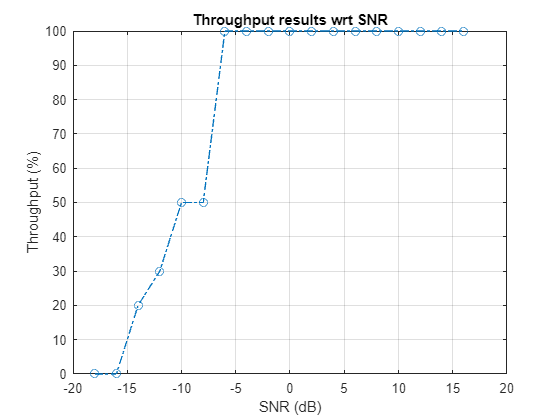

load(['./results/results_2_frames_all_snrs.mat'], 'simResults');
% Plotting the results 
figure;
plot(simResults.simParameters.SNRIn,simResults.simThroughput*100./simResults.maxThroughput,'o-.')
xlabel('SNR (dB)'); ylabel('Throughput (%)'); grid on;
title("Throughput results wrt SNR");

## Computing throughput in Different Locations

In this section, we will compare the throughput between two location (LOS and NLOS) chosen at random. 

experiments = ["LOS", "NLOS";];
snr_test = (-20:2:10);
NFrames = 2;
for i=1:length(experiments)
    idx_rx = randsample(find(pathData.linkState==i), 1);
    rxPos1 = rxPos(idx_rx,:);
    
    pl_rx = pathData.pl(idx_rx,:)';
    dly_rx = pathData.dly(idx_rx,:)';
    gain_rx = pathData.gain(idx_rx,:)';
    aoaAz = pathData.aoaAz(idx_rx,:)';
    aoaEl = pathData.aoaEl(idx_rx,:)';
    aodAz = pathData.aodAz(idx_rx,:)';
    aodEl = pathData.aodEl(idx_rx,:)';

    simParameters = struct();       % Clear simParameters variable to contain all key simulation parameters
    simParameters.NFrames = NFrames;      % Number of 10 ms frames
    % simParameters.SNRIn = [-20 -10]; % SNR range (dB)
    simParameters.SNRIn = snr_test; % SNR range (dB)
    simParameters.nscPerRB = 12;  % number of sub-carriers per RB
    simParameters.PerfectChannelEstimator = true;
    simParameters.DisplaySimulationInformation = false;
    simParameters.DisplayDiagnostics = false;
    
    % Set waveform type and PDSCH numerology (SCS and CP type)
    
    simParameters.Carrier = nrCarrierConfig( ...
        'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing, ...
        'CyclicPrefix','normal', 'NCellID',1);
    
    simParameters.waveformConfig =  nrOFDMInfo(simParameters.Carrier);
    
    % PDSCH/DL-SCH parameters
    simParameters.PDSCH = nrPDSCHConfig;      % This PDSCH definition is the basis for all PDSCH transmissions in the BLER simulation
    simParameters.PDSCHExtension = struct();  % This structure is to hold additional simulation parameters for the DL-SCH and PDSCH
    
    % Define PDSCH time-frequency resource allocation per slot to be full grid (single full grid BWP)
    simParameters.PDSCH.PRBSet = (0:simParameters.Carrier.NSizeGrid-1);                 % PDSCH PRB allocation
    simParameters.PDSCH.SymbolAllocation = [0,simParameters.Carrier.SymbolsPerSlot];  % Starting symbol and number of symbols of each PDSCH allocation
    simParameters.PDSCH.MappingType = 'A';     % PDSCH mapping type ('A'(slot-wise),'B'(non slot-wise))
    
    % Scrambling identifiers
    simParameters.PDSCH.NID = simParameters.Carrier.NCellID;
    simParameters.PDSCH.RNTI = 1;
    
    % PDSCH resource block mapping (TS 38.211 Section 7.3.1.6)
    simParameters.PDSCH.VRBToPRBInterleaving = 0; % Disable interleaved resource mapping
    simParameters.PDSCH.VRBBundleSize = 4;
    
    % Define the number of transmission layers to be used
    simParameters.PDSCH.NumLayers = 2;            % Number of PDSCH transmission layers
    
    if simParameters.PDSCH.NumCodewords > 1                             % Multicodeword transmission (when number of layers being > 4)
        simParameters.PDSCH.Modulation = {'16QAM','16QAM'};             % 'QPSK', '16QAM', '64QAM', '256QAM'
        simParameters.PDSCHExtension.TargetCodeRate = [490 490]/1024;   % Code rate used to calculate transport block sizes
    else
        simParameters.PDSCH.Modulation = '16QAM';                       % 'QPSK', '16QAM', '64QAM', '256QAM'
        simParameters.PDSCHExtension.TargetCodeRate = 490/1024;         % Code rate used to calculate transport block sizes
    end
    
    % DM-RS and antenna port configuration (TS 38.211 Section 7.4.1.1)
    simParameters.PDSCH.DMRS.DMRSPortSet = 0:simParameters.PDSCH.NumLayers-1; % DM-RS ports to use for the layers
    simParameters.PDSCH.DMRS.DMRSTypeAPosition = 2;      % Mapping type A only. First DM-RS symbol position (2,3)
    simParameters.PDSCH.DMRS.DMRSLength = 1;             % Number of front-loaded DM-RS symbols (1(single symbol),2(double symbol))
    simParameters.PDSCH.DMRS.DMRSAdditionalPosition = 2; % Additional DM-RS symbol positions (max range 0...3)
    simParameters.PDSCH.DMRS.DMRSConfigurationType = 2;  % DM-RS configuration type (1,2)
    simParameters.PDSCH.DMRS.NumCDMGroupsWithoutData = 1;% Number of CDM groups without data
    simParameters.PDSCH.DMRS.NIDNSCID = 1;               % Scrambling identity (0...65535)
    simParameters.PDSCH.DMRS.NSCID = 0;                  % Scrambling initialization (0,1)
    
    % PT-RS configuration (TS 38.211 Section 7.4.1.2)
    simParameters.PDSCH.EnablePTRS = 0;                  % Enable or disable PT-RS (1 or 0)
    simParameters.PDSCH.PTRS.TimeDensity = 1;            % PT-RS time density (L_PT-RS) (1, 2, 4)
    simParameters.PDSCH.PTRS.FrequencyDensity = 2;       % PT-RS frequency density (K_PT-RS) (2 or 4)
    simParameters.PDSCH.PTRS.REOffset = '00';            % PT-RS resource element offset ('00', '01', '10', '11')
    simParameters.PDSCH.PTRS.PTRSPortSet = [];           % PT-RS antenna port, subset of DM-RS port set. Empty corresponds to lower DM-RS port number
    
    % Reserved PRB patterns, if required (for CORESETs, forward compatibility etc)
    simParameters.PDSCH.ReservedPRB{1}.SymbolSet = [];   % Reserved PDSCH symbols
    simParameters.PDSCH.ReservedPRB{1}.PRBSet = [];      % Reserved PDSCH PRBs
    simParameters.PDSCH.ReservedPRB{1}.Period = [];      % Periodicity of reserved resources
     
    % Additional simulation and DL-SCH related parameters
    
    % PDSCH PRB bundling (TS 38.214 Section 5.1.2.3)
    simParameters.PDSCHExtension.PRGBundleSize = [];     % 2, 4, or [] to signify "wideband"
    
    % HARQ process and rate matching/TBS parameters
    simParameters.PDSCHExtension.XOverhead = 6*simParameters.PDSCH.EnablePTRS; % Set PDSCH rate matching overhead for TBS (Xoh) to 6 when PT-RS is enabled, otherwise 0
    simParameters.PDSCHExtension.NHARQProcesses = 8;    % Number of parallel HARQ processes to use
    simParameters.PDSCHExtension.EnableHARQ = true;      % Enable retransmissions for each process, using RV sequence [0,2,3,1]
    
    % LDPC decoder parameters
    % Available algorithms: 'Belief propagation', 'Layered belief propagation', 'Normalized min-sum', 'Offset min-sum'
    simParameters.PDSCHExtension.LDPCDecodingAlgorithm = 'Normalized min-sum';
    simParameters.PDSCHExtension.MaximumLDPCIterationCount = 6;
    
    % Define the overall transmission antenna geometry at end-points
    % If using a CDL propagation channel then the integer number of antenna elements is
    % turned into an antenna panel configured when the channel model object is created
    simParameters.NTxAnts = arrPlatformTx.getNumElements();
    simParameters.NRxAnts = arrPlatformRx.getNumElements();
    
    % Define the general CDL/TDL propagation channel parameters
    simParameters.DelayProfile = 'Custom';   % Use CDL-C model (Urban macrocell model)
    
    % Cross-check the PDSCH layering against the channel geometry
    validateNumLayers(simParameters);
    % The simulation relies on various pieces of information about the baseband waveform, such as sample rate.
    
    waveformInfo = nrOFDMInfo(simParameters.Carrier); % Get information about the baseband waveform after OFDM modulation step
    % Propagation Channel Model Construction
    % Create the channel model object for the simulation. Both CDL and TDL channel models are supported [ 5 ].
    
    % CDL channel object
    valid_paths = ~isnan(dly_rx);
    channel = nrCDLChannel('DelayProfile','Custom', 'PathDelays',dly_rx(valid_paths)', 'AveragePathGains',gain_rx(valid_paths)', ...
            'AnglesAoA',aoaAz(valid_paths)', 'AnglesAoD',aodAz(valid_paths)', 'AnglesZoA',90-aoaEl(valid_paths)', ...
            'AnglesZoD',90-aodEl(valid_paths)', 'HasLOSCluster',strcmp(experiments{i},"LOS"), 'CarrierFrequency', fc, 'SampleRate', waveformInfo.SampleRate, ...
            'TransmitAntennaArray',arrTx, 'ReceiveAntennaArray', arrRx);
    chInfo = info(channel);
    maxChDelay = chInfo.MaximumChannelDelay;
    
    % Array to store the maximum throughput for all SNR points
    maxThroughput = zeros(length(simParameters.SNRIn),1);
    % Array to store the simulation throughput for all SNR points
    simThroughput = zeros(length(simParameters.SNRIn),1);
    
    % Set up redundancy version (RV) sequence for all HARQ processes
    if simParameters.PDSCHExtension.EnableHARQ
        rvSeq = [0 2 3 1];
    else
        % HARQ disabled - single transmission with RV=0, no retransmissions
        rvSeq = 0;
    end
    
    % Create DL-SCH encoder system object to perform transport channel encoding
    encodeDLSCH = nrDLSCH;
    encodeDLSCH.MultipleHARQProcesses = true;
    encodeDLSCH.TargetCodeRate = simParameters.PDSCHExtension.TargetCodeRate;
    
    % Create DL-SCH decoder system object to perform transport channel decoding
    % Use layered belief propagation for LDPC decoding, with half the number of
    % iterations as compared to the default for belief propagation decoding
    decodeDLSCH = nrDLSCHDecoder;
    decodeDLSCH.MultipleHARQProcesses = true;
    decodeDLSCH.TargetCodeRate = simParameters.PDSCHExtension.TargetCodeRate;
    decodeDLSCH.LDPCDecodingAlgorithm = simParameters.PDSCHExtension.LDPCDecodingAlgorithm;
    decodeDLSCH.MaximumLDPCIterationCount = simParameters.PDSCHExtension.MaximumLDPCIterationCount;
    
    for snrIdx = 1:numel(simParameters.SNRIn)      % comment out for parallel computing
    % parfor snrIdx = 1:numel(simParameters.SNRIn) % uncomment for parallel computing    
        % Reset the random number generator so that each SNR point will
        % experience the same noise realization
        rng('default');
        % Take full copies of the simulation-level parameter structures so that they are not
        % PCT broadcast variables when using parfor
        simLocal = simParameters;
        waveinfoLocal = waveformInfo;
    
        % Take copies of channel-level parameters to simplify subsequent parameter referencing
        carrier = simLocal.Carrier;
        pdsch = simLocal.PDSCH;
        pdschextra = simLocal.PDSCHExtension;
        decodeDLSCHLocal = decodeDLSCH;  % Copy of the decoder handle to help PCT classification of variable
        decodeDLSCHLocal.reset();        % Reset decoder at the start of each SNR point
        pathFilters = [];
    
        % Prepare simulation for new SNR point
        SNRdB = simLocal.SNRIn(snrIdx);
        fprintf('\nSimulating transmission scheme 1 (%dx%d) and SCS=%dkHz with channel at %gdB SNR for %d 10ms frame(s)\n', ...
            simLocal.NTxAnts,simLocal.NRxAnts,carrier.SubcarrierSpacing,SNRdB,simLocal.NFrames);
    
        % Specify the fixed order in which we cycle through the HARQ process IDs
        harqSequence = 0:pdschextra.NHARQProcesses-1;
    
        % Initialize the state of all HARQ processes
        harqEntity = HARQEntity(harqSequence,rvSeq,pdsch.NumCodewords);
    
        % Reset the channel so that each SNR point will experience the same
        % channel realization
        reset(channel);
        
        % Total number of slots in the simulation period
        NSlots = simLocal.NFrames * carrier.SlotsPerFrame;
    
        % Obtain a precoding matrix (wtx) to be used in the transmission of the
        % first transport block
        estChannelGrid = getInitialChannelEstimate(carrier,simLocal.NTxAnts,channel);    
        newWtx = getPrecodingMatrix(carrier,pdsch,estChannelGrid,pdschextra.PRGBundleSize);
        
        % Timing offset, updated in every slot for perfect synchronization and
        % when the correlation is strong for practical synchronization
        offset = 0;
    
        % Loop over the entire waveform length
        for nslot = 0:NSlots-1
    
            % Update the carrier slot numbers for new slot
            carrier.NSlot = nslot;
    
            % Calculate the transport block sizes for the transmission in the slot
            [pdschIndices,pdschIndicesInfo] = nrPDSCHIndices(carrier,pdsch);
            trBlkSizes = nrTBS(pdsch.Modulation,pdsch.NumLayers,numel(pdsch.PRBSet),pdschIndicesInfo.NREPerPRB,pdschextra.TargetCodeRate,pdschextra.XOverhead);
            
            % HARQ processing
            for cwIdx = 1:pdsch.NumCodewords
                % If new data for current process and codeword then create a new DL-SCH transport block
                if harqEntity.NewData(cwIdx)
                    trBlk = randi([0 1],trBlkSizes(cwIdx),1);
                    setTransportBlock(encodeDLSCH,trBlk,cwIdx-1,harqEntity.HARQProcessID);
                    % If new data because of previous RV sequence time out then flush decoder soft buffer explicitly
                    if harqEntity.SequenceTimeout(cwIdx)
                        resetSoftBuffer(decodeDLSCHLocal,cwIdx-1,harqEntity.HARQProcessID);
                    end
                end
            end
    
            % Encode the DL-SCH transport blocks
            codedTrBlocks = encodeDLSCH(pdsch.Modulation,pdsch.NumLayers, ...
                pdschIndicesInfo.G,harqEntity.RedundancyVersion,harqEntity.HARQProcessID);
            
            % Get precoding matrix (wtx) calculated in previous slot
            wtx = newWtx;
            
            % Create resource grid for a slot
            pdschGrid = nrResourceGrid(carrier,simLocal.NTxAnts);
    
            % PDSCH modulation and precoding
            pdschSymbols = nrPDSCH(carrier,pdsch,codedTrBlocks);
            [pdschAntSymbols,pdschAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,pdschSymbols,pdschIndices,wtx);
    
            % PDSCH mapping in grid associated with PDSCH transmission period
            pdschGrid(pdschAntIndices) = pdschAntSymbols;
    
            % PDSCH DM-RS precoding and mapping
            dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
            dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);
            [dmrsAntSymbols,dmrsAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,dmrsSymbols,dmrsIndices,wtx);
            pdschGrid(dmrsAntIndices) = dmrsAntSymbols;
    
            % PDSCH PT-RS precoding and mapping
            ptrsSymbols = nrPDSCHPTRS(carrier,pdsch);
            ptrsIndices = nrPDSCHPTRSIndices(carrier,pdsch);
            [ptrsAntSymbols,ptrsAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,ptrsSymbols,ptrsIndices,wtx);
            pdschGrid(ptrsAntIndices) = ptrsAntSymbols;
    
            % OFDM modulation
            
            txWaveform = nrOFDMModulate(carrier,pdschGrid);
            txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))]; %#ok<AGROW>
            [rxWaveform,pathGains,sampleTimes] = channel(txWaveform);
            
    
            SNR = 10^(SNRdB/10);
            N0 = 1/sqrt(2.0*simLocal.NRxAnts*double(waveinfoLocal.Nfft)*SNR);
            noise = N0*complex(randn(size(rxWaveform)),randn(size(rxWaveform)));
            rxWaveform = rxWaveform + noise;
            
            if (simLocal.PerfectChannelEstimator)
                % Perfect synchronization. Use information provided by the
                % channel to find the strongest multipath component
                pathFilters = getPathFilters(channel);
                [offset,mag] = nrPerfectTimingEstimate(pathGains,pathFilters);
            else
                [t,mag] = nrTimingEstimate(carrier,rxWaveform,dmrsIndices,dmrsSymbols);
                offset = hSkipWeakTimingOffset(offset,t,mag);
                % Display a warning if the estimated timing offset exceeds the
                % maximum channel delay
                if offset > maxChDelay
                    warning(['Estimated timing offset (%d) is greater than the maximum channel delay (%d).' ...
                        ' This will result in a decoding failure. This may be caused by low SNR,' ...
                        ' or not enough DM-RS symbols to synchronize successfully.'],offset,maxChDelay);
                end
            end
            rxWaveform = rxWaveform(1+offset:end,:);
            rxGrid = nrOFDMDemodulate(carrier,rxWaveform);
            [K,L,R] = size(rxGrid);
            if (L < carrier.SymbolsPerSlot)
                rxGrid = cat(2,rxGrid,zeros(K,carrier.SymbolsPerSlot-L,R));
            end
            if (simLocal.PerfectChannelEstimator)
                estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);
    
                % Get perfect noise estimate (from the noise realization)
                noiseGrid = nrOFDMDemodulate(carrier,noise(1+offset:end ,:));
                noiseEst = var(noiseGrid(:));
                
                % Get precoding matrix for next slot
                newWtx = getPrecodingMatrix(carrier,pdsch,estChannelGrid,pdschextra.PRGBundleSize);
    
                % Get PDSCH resource elements from the received grid and
                % channel estimate
                [pdschRx,pdschHest,~,pdschHestIndices] = nrExtractResources(pdschIndices,rxGrid,estChannelGrid);
                
                % Apply precoding to channel estimate
                pdschHest = hPRGPrecode(size(estChannelGrid),carrier.NStartGrid,pdschHest,pdschHestIndices,permute(wtx,[2 1 3]));
            else
                [estChannelGrid,noiseEst] = hSubbandChannelEstimate(carrier,rxGrid,dmrsIndices,dmrsSymbols,pdschextra.PRGBundleSize,'CDMLengths',pdsch.DMRS.CDMLengths);
                
                % Average noise estimate across PRGs and layers
                noiseEst = mean(noiseEst,'all');
    
                % Get PDSCH resource elements from the received grid and
                % channel estimate
                [pdschRx,pdschHest] = nrExtractResources(pdschIndices,rxGrid,estChannelGrid);
    
                % Remove precoding from estChannelGrid prior to precoding
                % matrix calculation
                estChannelGridPorts = precodeChannelEstimate(carrier,estChannelGrid,conj(wtx));
           
                % Get precoding matrix for next slot
                newWtx = getPrecodingMatrix(carrier,pdsch,estChannelGridPorts,pdschextra.PRGBundleSize);
            end
            
            % Equalization
            % This is what needs to be done         
            [pdschEq,csi] = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);
    
            % Common phase error (CPE) compensation
            if ~isempty(ptrsIndices)
                
                % Initialize temporary grid to store equalized symbols
                tempGrid = nrResourceGrid(carrier,pdsch.NumLayers);
    
                % Extract PT-RS symbols from received grid and estimated
                % channel grid
                [ptrsRx,ptrsHest,~,~,ptrsHestIndices,ptrsLayerIndices] = nrExtractResources(ptrsIndices,rxGrid,estChannelGrid,tempGrid);
    
                if (simLocal.PerfectChannelEstimator)
                    % Apply precoding to channel estimate
                    ptrsHest = hPRGPrecode(size(estChannelGrid),carrier.NStartGrid,ptrsHest,ptrsHestIndices,permute(wtx,[2 1 3]));
                end
    
                % Equalize PT-RS symbols and map them to tempGrid
                ptrsEq = nrEqualizeMMSE(ptrsRx,ptrsHest,noiseEst);
                tempGrid(ptrsLayerIndices) = ptrsEq;
    
                % Estimate the residual channel at the PT-RS locations in
                % tempGrid
                cpe = nrChannelEstimate(tempGrid,ptrsIndices,ptrsSymbols);
    
                % Sum estimates across subcarriers, receive antennas, and
                % layers. Then, get the CPE by taking the angle of the
                % resultant sum
                cpe = angle(sum(cpe,[1 3 4]));
    
                % Map the equalized PDSCH symbols to tempGrid
                tempGrid(pdschIndices) = pdschEq;
    
                % Correct CPE in each OFDM symbol within the range of reference
                % PT-RS OFDM symbols
                symLoc = pdschIndicesInfo.PTRSSymbolSet(1)+1:pdschIndicesInfo.PTRSSymbolSet(end)+1;
                tempGrid(:,symLoc,:) = tempGrid(:,symLoc,:).*exp(-1i*cpe(symLoc));
    
                % Extract PDSCH symbols
                pdschEq = tempGrid(pdschIndices);
            end
            
            % Decode PDSCH physical channel
            [dlschLLRs,rxSymbols] = nrPDSCHDecode(carrier,pdsch,pdschEq,noiseEst);
    
            % Display EVM per layer, per slot and per RB
            if (simLocal.DisplayDiagnostics)
                plotLayerEVM(NSlots,nslot,pdsch,size(pdschGrid),pdschIndices,pdschSymbols,pdschEq);
            end
            
            % Scale LLRs by CSI
            csi = nrLayerDemap(csi); % CSI layer demapping
    
            for cwIdx = 1:pdsch.NumCodewords
                Qm = length(dlschLLRs{cwIdx})/length(rxSymbols{cwIdx}); % bits per symbol
                csi{cwIdx} = repmat(csi{cwIdx}.',Qm,1);                 % expand by each bit per symbol
                dlschLLRs{cwIdx} = dlschLLRs{cwIdx} .* csi{cwIdx}(:);   % scale by CSI
            end
    
            % Decode the DL-SCH transport channel
            decodeDLSCHLocal.TransportBlockLength = trBlkSizes;
            [decbits,blkerr] = decodeDLSCHLocal(dlschLLRs,pdsch.Modulation,pdsch.NumLayers,harqEntity.RedundancyVersion,harqEntity.HARQProcessID);
            
            % Store values to calculate throughput
            simThroughput(snrIdx) = simThroughput(snrIdx) + sum(~blkerr .* trBlkSizes);
            maxThroughput(snrIdx) = maxThroughput(snrIdx) + sum(trBlkSizes);
    
            % Update current process with CRC error and advance to next process
            procstatus = updateAndAdvance(harqEntity,blkerr,trBlkSizes,pdschIndicesInfo.G);
            if (simLocal.DisplaySimulationInformation)
                fprintf('\n(%3.2f%%) NSlot=%d, %s',100*(nslot+1)/NSlots,nslot,procstatus);
            end
    
         end
    
        % Display the results dynamically in the command window
        if (simLocal.DisplaySimulationInformation)
            fprintf('\n');
        end
        fprintf('\nThroughput(Mbps) for %d frame(s) = %.4f\n',simLocal.NFrames,1e-6*simThroughput(snrIdx)/(simLocal.NFrames*10e-3));
        fprintf('Throughput(%%) for %d frame(s) = %.4f\n',simLocal.NFrames,simThroughput(snrIdx)*100/maxThroughput(snrIdx));

        simResults.simParameters = simParameters;
        simResults.simThroughput = simThroughput;
        simResults.maxThroughput = maxThroughput;
        save(['./results/results_2_frames_all_snrs_', experiments{i}, '.mat'],'simResults');
    end
end

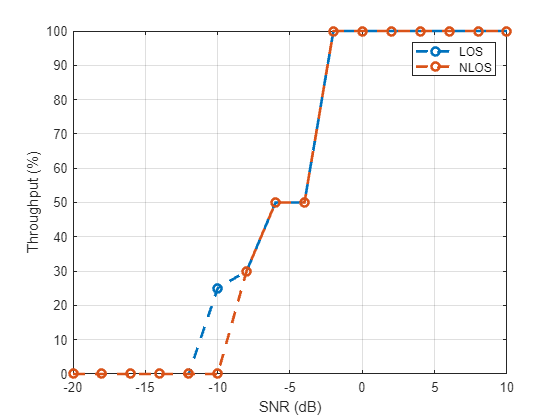

experiments = ["LOS", "NLOS";];
clf;
for i=1:length(experiments)
    load(['./results/results_2_frames_all_snrs_', experiments{i}, '.mat'],'simResults');
    plot(simResults.simParameters.SNRIn,simResults.simThroughput*100./simResults.maxThroughput,"o--", 'LineWidth', 2)
    hold on;
end
hold off;
xlabel('SNR (dB)'); ylabel('Throughput (%)'); grid on;
legend(experiments);

## SNR as function of the distance from the Transmitter at different SNRS

In this section, we will compute the throughput as a function of the Tx-Rx distance for both LOS and NLOS positions. We will plot for different values of Transmitter power in dBm. 

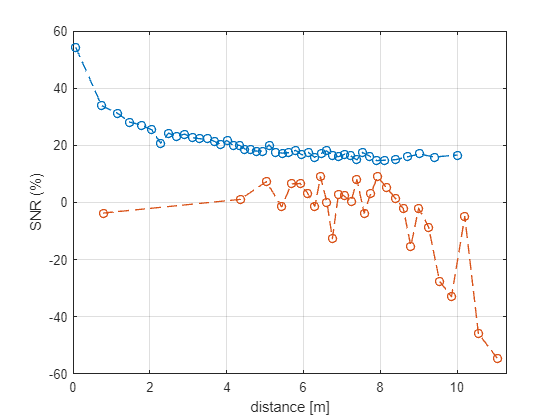

% Parameters to compute the SNR at different locations
txPow = 15;  % TX power in dBm
nf = 7;      % Noise figure
bw = 850e6;  % Bandwidth
Ekt = -174;  % Theremal noise

distances = sqrt(sum((pathData.txPos' - pathData.rxPos).^2,2));
[d,Ind]  = sort(distances);

% Find the index in the ray tracing data closest to the desired position
Ind = [Ind pathData.linkState(Ind)];
Ind1 = Ind(Ind(:,2)==1);
Ind1 = Ind1((1:75:length(Ind1)));
Ind2 = Ind(Ind(:,2)==2);
Ind2 = Ind2((1:50:length(Ind2)));
distanceslos = distances(Ind1);
distancesnlos = distances(Ind2);
% Get the path loss data
plos = pathData.pl;
npos = length(Ind1);
npos2 = length(Ind2);
snrValues = zeros(npos,1);
snrValuesNlos = zeros(npos2,1); 

% Loop over the locations and compute the RX power
for idx = 1:npos
    i = Ind1(idx);
    k = pathData.npaths(i); 
    if k >  0
        rxPow =  txPow + pow2db(sum(db2pow(-plos(i,1:k))));
        snrValues(idx) = rxPow - nf - Ekt - 10*log10(bw);
    end
end

% Loop over the locations and compute the RX power
for idx2 = 1:npos2
    i = Ind2(idx2);
    k = pathData.npaths(i); 
    if k >  0
        rxPow =  txPow + pow2db(sum(db2pow(-plos(i,1:k))));
        snrValuesNlos(idx2) = rxPow - nf - Ekt - 10*log10(bw);
    end
end

% Plot the Path loss ad function of the distance

plot(distanceslos, snrValues,"o--", 'LineWidth', 1);
hold on;
plot(distancesnlos, snrValuesNlos,"o--", 'LineWidth', 1);
hold off;
xlabel('distance [m]'); ylabel('SNR (%)'); grid on;
xlim([0 11.3]);

## Throughput with Practical Channel Estimation using DM-RS

We compute now the throughput of the system under realistic settings with Practical channel Estimation. 

simParameters = struct();       % Clear simParameters variable to contain all key simulation parameters
simParameters.NFrames = 2;      % Number of 10 ms frames
% simParameters.SNRIn = [-20 -10]; % SNR range (dB)
simParameters.SNRIn = (-18:2:16); % SNR range (dB)
simParameters.nscPerRB = 12;  % number of sub-carriers per RB
simParameters.PerfectChannelEstimator = false;
simParameters.DisplaySimulationInformation = false;
simParameters.DisplayDiagnostics = false;

% Set waveform type and PDSCH numerology (SCS and CP type)

simParameters.Carrier = nrCarrierConfig( ...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing, ...
    'CyclicPrefix','normal', 'NCellID',1);

simParameters.waveformConfig =  nrOFDMInfo(simParameters.Carrier);

% PDSCH/DL-SCH parameters
simParameters.PDSCH = nrPDSCHConfig;      % This PDSCH definition is the basis for all PDSCH transmissions in the BLER simulation
simParameters.PDSCHExtension = struct();  % This structure is to hold additional simulation parameters for the DL-SCH and PDSCH

% Define PDSCH time-frequency resource allocation per slot to be full grid (single full grid BWP)
simParameters.PDSCH.PRBSet = (0:simParameters.Carrier.NSizeGrid-1);                 % PDSCH PRB allocation
simParameters.PDSCH.SymbolAllocation = [0,simParameters.Carrier.SymbolsPerSlot];  % Starting symbol and number of symbols of each PDSCH allocation
simParameters.PDSCH.MappingType = 'A';     % PDSCH mapping type ('A'(slot-wise),'B'(non slot-wise))

% Scrambling identifiers
simParameters.PDSCH.NID = simParameters.Carrier.NCellID;
simParameters.PDSCH.RNTI = 1;

% PDSCH resource block mapping (TS 38.211 Section 7.3.1.6)
simParameters.PDSCH.VRBToPRBInterleaving = 0; % Disable interleaved resource mapping
simParameters.PDSCH.VRBBundleSize = 4;

% Define the number of transmission layers to be used
simParameters.PDSCH.NumLayers = 2;            % Number of PDSCH transmission layers

% Define codeword modulation and target coding rate
% The number of codewords is directly dependent on the number of layers so ensure that
% layers are set first before getting the codeword number
if simParameters.PDSCH.NumCodewords > 1                             % Multicodeword transmission (when number of layers being > 4)
    simParameters.PDSCH.Modulation = {'16QAM','16QAM'};             % 'QPSK', '16QAM', '64QAM', '256QAM'
    simParameters.PDSCHExtension.TargetCodeRate = [490 490]/1024;   % Code rate used to calculate transport block sizes
else
    simParameters.PDSCH.Modulation = '16QAM';                       % 'QPSK', '16QAM', '64QAM', '256QAM'
    simParameters.PDSCHExtension.TargetCodeRate = 490/1024;         % Code rate used to calculate transport block sizes
end

% DM-RS and antenna port configuration (TS 38.211 Section 7.4.1.1)
simParameters.PDSCH.DMRS.DMRSPortSet = 0:simParameters.PDSCH.NumLayers-1; % DM-RS ports to use for the layers
simParameters.PDSCH.DMRS.DMRSTypeAPosition = 2;      % Mapping type A only. First DM-RS symbol position (2,3)
simParameters.PDSCH.DMRS.DMRSLength = 1;             % Number of front-loaded DM-RS symbols (1(single symbol),2(double symbol))
simParameters.PDSCH.DMRS.DMRSAdditionalPosition = 2; % Additional DM-RS symbol positions (max range 0...3)
simParameters.PDSCH.DMRS.DMRSConfigurationType = 2;  % DM-RS configuration type (1,2)
simParameters.PDSCH.DMRS.NumCDMGroupsWithoutData = 1;% Number of CDM groups without data
simParameters.PDSCH.DMRS.NIDNSCID = 1;               % Scrambling identity (0...65535)
simParameters.PDSCH.DMRS.NSCID = 0;                  % Scrambling initialization (0,1)

% PT-RS configuration (TS 38.211 Section 7.4.1.2)
simParameters.PDSCH.EnablePTRS = 0;                  % Enable or disable PT-RS (1 or 0)
simParameters.PDSCH.PTRS.TimeDensity = 1;            % PT-RS time density (L_PT-RS) (1, 2, 4)
simParameters.PDSCH.PTRS.FrequencyDensity = 2;       % PT-RS frequency density (K_PT-RS) (2 or 4)
simParameters.PDSCH.PTRS.REOffset = '00';            % PT-RS resource element offset ('00', '01', '10', '11')
simParameters.PDSCH.PTRS.PTRSPortSet = [];           % PT-RS antenna port, subset of DM-RS port set. Empty corresponds to lower DM-RS port number

% Reserved PRB patterns, if required (for CORESETs, forward compatibility etc)
simParameters.PDSCH.ReservedPRB{1}.SymbolSet = [];   % Reserved PDSCH symbols
simParameters.PDSCH.ReservedPRB{1}.PRBSet = [];      % Reserved PDSCH PRBs
simParameters.PDSCH.ReservedPRB{1}.Period = [];      % Periodicity of reserved resources
 
% Additional simulation and DL-SCH related parameters

% PDSCH PRB bundling (TS 38.214 Section 5.1.2.3)
simParameters.PDSCHExtension.PRGBundleSize = [];     % 2, 4, or [] to signify "wideband"

% HARQ process and rate matching/TBS parameters
simParameters.PDSCHExtension.XOverhead = 6*simParameters.PDSCH.EnablePTRS; % Set PDSCH rate matching overhead for TBS (Xoh) to 6 when PT-RS is enabled, otherwise 0
simParameters.PDSCHExtension.NHARQProcesses = 16;    % Number of parallel HARQ processes to use
simParameters.PDSCHExtension.EnableHARQ = true;      % Enable retransmissions for each process, using RV sequence [0,2,3,1]

% LDPC decoder parameters
% Available algorithms: 'Belief propagation', 'Layered belief propagation', 'Normalized min-sum', 'Offset min-sum'
simParameters.PDSCHExtension.LDPCDecodingAlgorithm = 'Normalized min-sum';
simParameters.PDSCHExtension.MaximumLDPCIterationCount = 6;

% Define the overall transmission antenna geometry at end-points
% If using a CDL propagation channel then the integer number of antenna elements is
% turned into an antenna panel configured when the channel model object is created
simParameters.NTxAnts = arrPlatformTx.getNumElements();
simParameters.NRxAnts = arrPlatformRx.getNumElements();

% Define the general CDL/TDL propagation channel parameters
simParameters.DelayProfile = 'Custom';   % Use CDL-C model (Urban macrocell model)

% Cross-check the PDSCH layering against the channel geometry
validateNumLayers(simParameters);
% The simulation relies on various pieces of information about the baseband waveform, such as sample rate.

waveformInfo = nrOFDMInfo(simParameters.Carrier); % Get information about the baseband waveform after OFDM modulation step
% Propagation Channel Model Construction
% Create the channel model object for the simulation. Both CDL and TDL channel models are supported [ 5 ].

% CDL channel object
channel = nrCDLChannel('DelayProfile','Custom', 'PathDelays',dly_rx', 'AveragePathGains',gain_rx', ...
    'AnglesAoA',aoaAz', 'AnglesAoD',aodAz', 'AnglesZoA',90-aoaEl', 'AnglesZoD',90-aodEl', ...
    'HasLOSCluster',true, 'CarrierFrequency', fc, 'SampleRate', waveformInfo.SampleRate, ...
    'TransmitAntennaArray',arrTx, 'ReceiveAntennaArray', arrRx);

chInfo = info(channel);
maxChDelay = chInfo.MaximumChannelDelay;

% Array to store the maximum throughput for all SNR points
maxThroughput = zeros(length(simParameters.SNRIn),1);
% Array to store the simulation throughput for all SNR points
simThroughput = zeros(length(simParameters.SNRIn),1);

% Set up redundancy version (RV) sequence for all HARQ processes
if simParameters.PDSCHExtension.EnableHARQ
    rvSeq = [0 2 3 1];
else
    % HARQ disabled - single transmission with RV=0, no retransmissions
    rvSeq = 0;
end

% Create DL-SCH encoder system object to perform transport channel encoding
encodeDLSCH = nrDLSCH;
encodeDLSCH.MultipleHARQProcesses = true;
encodeDLSCH.TargetCodeRate = simParameters.PDSCHExtension.TargetCodeRate;

% Create DL-SCH decoder system object to perform transport channel decoding
% Use layered belief propagation for LDPC decoding, with half the number of
% iterations as compared to the default for belief propagation decoding
decodeDLSCH = nrDLSCHDecoder;
decodeDLSCH.MultipleHARQProcesses = true;
decodeDLSCH.TargetCodeRate = simParameters.PDSCHExtension.TargetCodeRate;
decodeDLSCH.LDPCDecodingAlgorithm = simParameters.PDSCHExtension.LDPCDecodingAlgorithm;
decodeDLSCH.MaximumLDPCIterationCount = simParameters.PDSCHExtension.MaximumLDPCIterationCount;

for snrIdx = 1:numel(simParameters.SNRIn)      % comment out for parallel computing
% parfor snrIdx = 1:numel(simParameters.SNRIn) % uncomment for parallel computing
% To reduce the total simulation time, you can execute this loop in
% parallel by using the Parallel Computing Toolbox. Comment out the 'for'
% statement and uncomment the 'parfor' statement. If the Parallel Computing
% Toolbox is not installed, 'parfor' defaults to normal 'for' statement.
% Because parfor-loop iterations are executed in parallel in a
% nondeterministic order, the simulation information displayed for each SNR
% point can be intertwined. To switch off simulation information display,
% set the 'displaySimulationInformation' variable above to false

    % Reset the random number generator so that each SNR point will
    % experience the same noise realization
    rng('default');
    % Take full copies of the simulation-level parameter structures so that they are not
    % PCT broadcast variables when using parfor
    simLocal = simParameters;
    waveinfoLocal = waveformInfo;

    % Take copies of channel-level parameters to simplify subsequent parameter referencing
    carrier = simLocal.Carrier;
    pdsch = simLocal.PDSCH;
    pdschextra = simLocal.PDSCHExtension;
    decodeDLSCHLocal = decodeDLSCH;  % Copy of the decoder handle to help PCT classification of variable
    decodeDLSCHLocal.reset();        % Reset decoder at the start of each SNR point
    pathFilters = [];

    % Prepare simulation for new SNR point
    SNRdB = simLocal.SNRIn(snrIdx);
    fprintf('\nSimulating transmission scheme 1 (%dx%d) and SCS=%dkHz with channel at %gdB SNR for %d 10ms frame(s)\n', ...
        simLocal.NTxAnts,simLocal.NRxAnts,carrier.SubcarrierSpacing,SNRdB,simLocal.NFrames);

    % Specify the fixed order in which we cycle through the HARQ process IDs
    harqSequence = 0:pdschextra.NHARQProcesses-1;

    % Initialize the state of all HARQ processes
    harqEntity = HARQEntity(harqSequence,rvSeq,pdsch.NumCodewords);

    % Reset the channel so that each SNR point will experience the same
    % channel realization
    reset(channel);
    
    % Total number of slots in the simulation period
    NSlots = simLocal.NFrames * carrier.SlotsPerFrame;

    % Obtain a precoding matrix (wtx) to be used in the transmission of the
    % first transport block
    estChannelGrid = getInitialChannelEstimate(carrier,simLocal.NTxAnts,channel);    
    newWtx = getPrecodingMatrix(carrier,pdsch,estChannelGrid,pdschextra.PRGBundleSize);
    
    % Timing offset, updated in every slot for perfect synchronization and
    % when the correlation is strong for practical synchronization
    offset = 0;

    % Loop over the entire waveform length
    for nslot = 0:NSlots-1

        % Update the carrier slot numbers for new slot
        carrier.NSlot = nslot;

        % Calculate the transport block sizes for the transmission in the slot
        [pdschIndices,pdschIndicesInfo] = nrPDSCHIndices(carrier,pdsch);
        trBlkSizes = nrTBS(pdsch.Modulation,pdsch.NumLayers,numel(pdsch.PRBSet),pdschIndicesInfo.NREPerPRB,pdschextra.TargetCodeRate,pdschextra.XOverhead);
        
        % HARQ processing
        for cwIdx = 1:pdsch.NumCodewords
            % If new data for current process and codeword then create a new DL-SCH transport block
            if harqEntity.NewData(cwIdx)
                trBlk = randi([0 1],trBlkSizes(cwIdx),1);
                setTransportBlock(encodeDLSCH,trBlk,cwIdx-1,harqEntity.HARQProcessID);
                % If new data because of previous RV sequence time out then flush decoder soft buffer explicitly
                if harqEntity.SequenceTimeout(cwIdx)
                    resetSoftBuffer(decodeDLSCHLocal,cwIdx-1,harqEntity.HARQProcessID);
                end
            end
        end

        % Encode the DL-SCH transport blocks
        codedTrBlocks = encodeDLSCH(pdsch.Modulation,pdsch.NumLayers, ...
            pdschIndicesInfo.G,harqEntity.RedundancyVersion,harqEntity.HARQProcessID);
        
        % Get precoding matrix (wtx) calculated in previous slot
        wtx = newWtx;
        
        % Create resource grid for a slot
        pdschGrid = nrResourceGrid(carrier,simLocal.NTxAnts);

        % PDSCH modulation and precoding
        pdschSymbols = nrPDSCH(carrier,pdsch,codedTrBlocks);
        [pdschAntSymbols,pdschAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,pdschSymbols,pdschIndices,wtx);

        % PDSCH mapping in grid associated with PDSCH transmission period
        pdschGrid(pdschAntIndices) = pdschAntSymbols;

        % PDSCH DM-RS precoding and mapping
        dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
        dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);
        [dmrsAntSymbols,dmrsAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,dmrsSymbols,dmrsIndices,wtx);
        pdschGrid(dmrsAntIndices) = dmrsAntSymbols;

        % PDSCH PT-RS precoding and mapping
        ptrsSymbols = nrPDSCHPTRS(carrier,pdsch);
        ptrsIndices = nrPDSCHPTRSIndices(carrier,pdsch);
        [ptrsAntSymbols,ptrsAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,ptrsSymbols,ptrsIndices,wtx);
        pdschGrid(ptrsAntIndices) = ptrsAntSymbols;

        % OFDM modulation
        
        txWaveform = nrOFDMModulate(carrier,pdschGrid);
        % Pass data through channel model. Append zeros at the end of the
        % transmitted waveform to flush channel content. These zeros take
        % into account any delay introduced in the channel. This is a mix
        % of multipath delay and implementation delay. This value may
        % change depending on the sampling rate, delay profile and delay
        % spread
        txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))]; %#ok<AGROW>
        [rxWaveform,pathGains,sampleTimes] = channel(txWaveform);
        

        % Add AWGN to the received time domain waveform
        % Normalize noise power by the IFFT size used in OFDM modulation,
        % as the OFDM modulator applies this normalization to the
        % transmitted waveform. Also normalize by the number of receive
        % antennas, as the channel model applies this normalization to the
        % received waveform, by default
        SNR = 10^(SNRdB/10);
        N0 = 1/sqrt(2.0*simLocal.NRxAnts*double(waveinfoLocal.Nfft)*SNR);
        noise = N0*complex(randn(size(rxWaveform)),randn(size(rxWaveform)));
        rxWaveform = rxWaveform + noise;
        
        if (simLocal.PerfectChannelEstimator)
            % Perfect synchronization. Use information provided by the
            % channel to find the strongest multipath component
            pathFilters = getPathFilters(channel);
            [offset,mag] = nrPerfectTimingEstimate(pathGains,pathFilters);
        else
            % Practical synchronization. Correlate the received waveform
            % with the PDSCH DM-RS to give timing offset estimate 't' and
            % correlation magnitude 'mag'. The function
            % hSkipWeakTimingOffset is used to update the receiver timing
            % offset. If the correlation peak in 'mag' is weak, the current
            % timing estimate 't' is ignored and the previous estimate
            % 'offset' is used
            [t,mag] = nrTimingEstimate(carrier,rxWaveform,dmrsIndices,dmrsSymbols);
            offset = hSkipWeakTimingOffset(offset,t,mag);
            % Display a warning if the estimated timing offset exceeds the
            % maximum channel delay
%             if offset > maxChDelay
%                 warning(['Estimated timing offset (%d) is greater than the maximum channel delay (%d).' ...
%                     ' This will result in a decoding failure. This may be caused by low SNR,' ...
%                     ' or not enough DM-RS symbols to synchronize successfully.'],offset,maxChDelay);
%             end
        end
        rxWaveform = rxWaveform(1+offset:end,:);
        
        % Perform OFDM demodulation on the received data to recreate the
        % resource grid, including padding in the event that practical
        % synchronization results in an incomplete slot being demodulated
        rxGrid = nrOFDMDemodulate(carrier,rxWaveform);
        [K,L,R] = size(rxGrid);
        if (L < carrier.SymbolsPerSlot)
            rxGrid = cat(2,rxGrid,zeros(K,carrier.SymbolsPerSlot-L,R));
        end
        if (simLocal.PerfectChannelEstimator)
            % Perfect channel estimation, using the value of the path gains
            % provided by the channel. This channel estimate does not
            % include the effect of transmitter precoding
            estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);

            % Get perfect noise estimate (from the noise realization)
            noiseGrid = nrOFDMDemodulate(carrier,noise(1+offset:end ,:));
            noiseEst = var(noiseGrid(:));
            
            % Get precoding matrix for next slot
            newWtx = getPrecodingMatrix(carrier,pdsch,estChannelGrid,pdschextra.PRGBundleSize);

            % Get PDSCH resource elements from the received grid and
            % channel estimate
            [pdschRx,pdschHest,~,pdschHestIndices] = nrExtractResources(pdschIndices,rxGrid,estChannelGrid);
            
            % Apply precoding to channel estimate
            pdschHest = hPRGPrecode(size(estChannelGrid),carrier.NStartGrid,pdschHest,pdschHestIndices,permute(wtx,[2 1 3]));
        else
            % Practical channel estimation between the received grid and
            % each transmission layer, using the PDSCH DM-RS for each
            % layer. This channel estimate includes the effect of
            % transmitter precoding
%             [estChannelGrid,noiseEst] = hSubbandChannelEstimate(carrier,rxGrid,dmrsIndices,dmrsSymbols,pdschextra.PRGBundleSize,'CDMLengths',pdsch.DMRS.CDMLengths);
            [estChannelGrid,noiseEst] = nrChannelEstimate(carrier,rxGrid,dmrsIndices,dmrsSymbols,'CDMLengths',pdsch.DMRS.CDMLengths);

            % Average noise estimate across PRGs and layers
            noiseEst = mean(noiseEst,'all');

            % Get PDSCH resource elements from the received grid and
            % channel estimate
            [pdschRx,pdschHest] = nrExtractResources(pdschIndices,rxGrid,estChannelGrid);

            % Remove precoding from estChannelGrid prior to precoding
            % matrix calculation
            estChannelGridPorts = precodeChannelEstimate(carrier,estChannelGrid,conj(wtx));
       
            % Get precoding matrix for next slot
            newWtx = getPrecodingMatrix(carrier,pdsch,estChannelGridPorts,pdschextra.PRGBundleSize);
        end
        
        % Equalization
        % This is what needs to be done         
        [pdschEq,csi] = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);

        % Common phase error (CPE) compensation
        if ~isempty(ptrsIndices)
            
            % Initialize temporary grid to store equalized symbols
            tempGrid = nrResourceGrid(carrier,pdsch.NumLayers);

            % Extract PT-RS symbols from received grid and estimated
            % channel grid
            [ptrsRx,ptrsHest,~,~,ptrsHestIndices,ptrsLayerIndices] = nrExtractResources(ptrsIndices,rxGrid,estChannelGrid,tempGrid);

            if (simLocal.PerfectChannelEstimator)
                % Apply precoding to channel estimate
                ptrsHest = hPRGPrecode(size(estChannelGrid),carrier.NStartGrid,ptrsHest,ptrsHestIndices,permute(wtx,[2 1 3]));
            end

            % Equalize PT-RS symbols and map them to tempGrid
            ptrsEq = nrEqualizeMMSE(ptrsRx,ptrsHest,noiseEst);
            tempGrid(ptrsLayerIndices) = ptrsEq;

            % Estimate the residual channel at the PT-RS locations in
            % tempGrid
            cpe = nrChannelEstimate(tempGrid,ptrsIndices,ptrsSymbols);

            % Sum estimates across subcarriers, receive antennas, and
            % layers. Then, get the CPE by taking the angle of the
            % resultant sum
            cpe = angle(sum(cpe,[1 3 4]));

            % Map the equalized PDSCH symbols to tempGrid
            tempGrid(pdschIndices) = pdschEq;

            % Correct CPE in each OFDM symbol within the range of reference
            % PT-RS OFDM symbols
            symLoc = pdschIndicesInfo.PTRSSymbolSet(1)+1:pdschIndicesInfo.PTRSSymbolSet(end)+1;
            tempGrid(:,symLoc,:) = tempGrid(:,symLoc,:).*exp(-1i*cpe(symLoc));

            % Extract PDSCH symbols
            pdschEq = tempGrid(pdschIndices);
        end
        
        % Decode PDSCH physical channel
        [dlschLLRs,rxSymbols] = nrPDSCHDecode(carrier,pdsch,pdschEq,noiseEst);

        % Display EVM per layer, per slot and per RB
        if (simLocal.DisplayDiagnostics)
            plotLayerEVM(NSlots,nslot,pdsch,size(pdschGrid),pdschIndices,pdschSymbols,pdschEq);
        end
        
        % Scale LLRs by CSI
        csi = nrLayerDemap(csi); % CSI layer demapping

        for cwIdx = 1:pdsch.NumCodewords
            Qm = length(dlschLLRs{cwIdx})/length(rxSymbols{cwIdx}); % bits per symbol
            csi{cwIdx} = repmat(csi{cwIdx}.',Qm,1);                 % expand by each bit per symbol
            dlschLLRs{cwIdx} = dlschLLRs{cwIdx} .* csi{cwIdx}(:);   % scale by CSI
        end

        % Decode the DL-SCH transport channel
        decodeDLSCHLocal.TransportBlockLength = trBlkSizes;
        [decbits,blkerr] = decodeDLSCHLocal(dlschLLRs,pdsch.Modulation,pdsch.NumLayers,harqEntity.RedundancyVersion,harqEntity.HARQProcessID);
        
        % Store values to calculate throughput
        simThroughput(snrIdx) = simThroughput(snrIdx) + sum(~blkerr .* trBlkSizes);
        maxThroughput(snrIdx) = maxThroughput(snrIdx) + sum(trBlkSizes);

        % Update current process with CRC error and advance to next process
        procstatus = updateAndAdvance(harqEntity,blkerr,trBlkSizes,pdschIndicesInfo.G);
        if (simLocal.DisplaySimulationInformation)
            fprintf('\n(%3.2f%%) NSlot=%d, %s',100*(nslot+1)/NSlots,nslot,procstatus);
        end
     end

    % Display the results dynamically in the command window
    if (simLocal.DisplaySimulationInformation)
        fprintf('\n');
    end
    fprintf('\nThroughput(Mbps) for %d frame(s) = %.4f\n',simLocal.NFrames,1e-6*simThroughput(snrIdx)/(simLocal.NFrames*10e-3));
    fprintf('Throughput(%%) for %d frame(s) = %.4f\n',simLocal.NFrames,simThroughput(snrIdx)*100/maxThroughput(snrIdx));

end
% Bundle key parameters and results into a combined structure for recording
simResults.simParameters = simParameters;


Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at -18dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 0.0000


Throughput(%) for 2 frame(s) = 0.0000



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at -16dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 0.0000


Throughput(%) for 2 frame(s) = 0.0000



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at -14dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 0.0000


Throughput(%) for 2 frame(s) = 0.0000



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at -12dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 0.0000


Throughput(%) for 2 frame(s) = 0.0000



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at -10dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 0.0000


Throughput(%) for 2 frame(s) = 0.0000



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at -8dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 0.0000


Throughput(%) for 2 frame(s) = 0.0000



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at -6dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 0.0000


Throughput(%) for 2 frame(s) = 0.0000



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at -4dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 25.8272


Throughput(%) for 2 frame(s) = 8.7500



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at -2dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 29.5168


Throughput(%) for 2 frame(s) = 10.0000



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at 0dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 44.2752


Throughput(%) for 2 frame(s) = 15.0000



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at 2dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 44.2752


Throughput(%) for 2 frame(s) = 15.0000



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at 4dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 57.1888


Throughput(%) for 2 frame(s) = 19.3750



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at 6dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 73.7920


Throughput(%) for 2 frame(s) = 25.0000



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at 8dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 73.7920


Throughput(%) for 2 frame(s) = 25.0000



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at 10dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 129.1360


Throughput(%) for 2 frame(s) = 43.7500



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at 12dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 147.5840


Throughput(%) for 2 frame(s) = 50.0000



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at 14dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 147.5840


Throughput(%) for 2 frame(s) = 50.0000



Simulating transmission scheme 1 (16x8) and SCS=120kHz with channel at 16dB SNR for 2 10ms frame(s)



Throughput(Mbps) for 2 frame(s) = 147.5840


Throughput(%) for 2 frame(s) = 50.0000


simResults.simThroughput = simThroughput;
simResults.maxThroughput = maxThroughput;
save(['./results/results_no_prefect_channel_2_frames_all_snrs.mat'],'simResults');

load(['./results/results_2_frames_all_snrs.mat'], 'simResults');
% Plotting the results 
figure;
plot(simResults.simParameters.SNRIn,simResults.simThroughput*100./simResults.maxThroughput,'o-.');
hold on;
load(['./results/results_no_prefect_channel_2_frames_all_snrs.mat'], 'simResults');
% Plotting the results 
plot(simResults.simParameters.SNRIn,simResults.simThroughput*100./simResults.maxThroughput,'o-.')
hold off;
xlabel('SNR (dB)'); ylabel('Throughput (%)'); grid on;
title("Throughput results wrt SNR");
legend('Perfect Channel', 'Estimated Channel');

## Building a simplified version of the throughput simulation. 

In this section, we build our simplified version of the throughput simulation using the FDMIMO channel object and the Arrays defined above. We will do simulation between a LOS TX-RX pair and build Channel Estimators and Equalizer

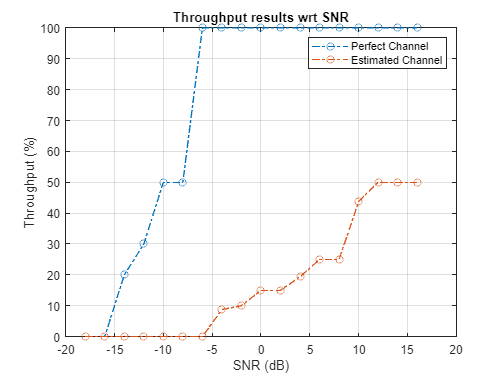

% We randomly choose a position and get the environment parameters

idx_rx = randsample(find(pathData.linkState==1), 1);

rxPos1 = rxPos(idx_rx,:);

pl_rx = pathData.pl(idx_rx,:)';
dly_rx = pathData.dly(idx_rx,:)';  
gain_rx = pathData.gain(idx_rx,:)';
aoaAz = pathData.aoaAz(idx_rx,:)';
aoaEl = pathData.aoaEl(idx_rx,:)';
aodAz = pathData.aodAz(idx_rx,:)';
aodEl = pathData.aodEl(idx_rx,:)';

% Assuming a TX power, compute the SNR using the path loss data
txPow = 15;  % TX power in dBm
nf = 7;      % Noise figure
bw = 850e6;  % Bandwidth
Ekt = -174;  % Theremal noise

npaths_rx = pathData.npaths(idx_rx); 
rxPow =  txPow + pow2db(sum(db2pow(-pathData.pl(idx_rx,1:npaths_rx))));
SNRdB = rxPow - nf - Ekt - 10*log10(bw);

fprintf(1, 'SNR at RX location: %.1f dB', SNRdB);

% We setup all the configurations

SubcarrierSpacing = 120; % SCS in kHZ
NRB = 61; % number of resource blocks
nscPerRB = 12; % number of sub-carriers per RB

% we get the carrierConfig and waveformConfig with the nrCarrierConfig and
% nrOFDMInfo methods in the 5G Toolbox.

SNR at RX location: 20.4 dB


carrierConfig = nrCarrierConfig( ...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);

dmrsConfig = nrPDSCHDMRSConfig(...
  'NumCDMGroupsWithoutData', 1, ...  % No unused DM-RS
  'DMRSAdditionalPosition', 1, ...   % Set this correctly
  'DMRSConfigurationType', 2);       % Set this correctly

% Configure the physical downlink shared channel parameters
pdschConfig = nrPDSCHConfig();
pdschConfig.NSizeBWP = [];   % Empty implies that the value is equal to NSizeGrid
pdschConfig.NStartBWP = [];  % Empty implies that the value is equal to NStartGrid
pdschConfig.PRBSet = (0:NRB-1);   % Allocate the complete carrier
pdschConfig.SymbolAllocation = [0 14]; % Symbol allocation [S L]
pdschConfig.MappingType = 'A'; % PDSCH mapping type ('A' or 'B')
pdschConfig.EnablePTRS = true;
pdschConfig.PTRS =  nrPDSCHPTRSConfig();
pdschConfig.DMRS = dmrsConfig;


Enoise = -5; % Energy per noise sample in dB

fdchan = FDMIMOChan( ...
    carrierConfig, 'txArrPlatform', arrPlatformTx, 'rxArrPlatform', arrPlatformRx, ...
    'aoaAz', aoaAz, 'aodAz', aodAz, 'aoaEl', aoaEl, 'aodEl', aodEl, ...
    'gain', gain_rx, 'dly', dly_rx, 'fc', fc, 'Enoise', Enoise);

% Compute throughput         
% Creating first the TXGrid

frameNum = 0;
slotNum = 0;
carrier = carrierConfig;
pdsch = pdschConfig;
% Update the carrier slot numbers for new slot
carrier.NSlot = slotNum;

% Calculate the transport block sizes for the transmission in the slot
[pdschIndices,pdschIndicesInfo] = nrPDSCHIndices(carrier,pdsch);
trBlkSizes = nrTBS(pdsch.Modulation,pdsch.NumLayers,numel(pdsch.PRBSet),pdschIndicesInfo.NREPerPRB,pdschextra.TargetCodeRate,pdschextra.XOverhead);
trBlk = randi([0 1],trBlkSizes(cwIdx),1);
setTransportBlock(encodeDLSCH,trBlk,cwIdx-1,harqEntity.HARQProcessID);
% Encode the DL-SCH transport blocks
codedTrBlocks = encodeDLSCH(pdsch.Modulation,pdsch.NumLayers, ...
    pdschIndicesInfo.G,harqEntity.RedundancyVersion,harqEntity.HARQProcessID);

% Get precoding matrix (wtx)
[chanGrid, noiseVar] = fdchan.step(frameNum, slotNum);
chanGrid = permute(chanGrid, [3 4 1 2]);
% We get the precoding matrix at the TX as if we knew the Channel Matrix
wtx = getPrecodingMatrix(carrier,pdsch,chanGrid,pdschextra.PRGBundleSize);

% Create resource grid for a slot
pdschGrid = nrResourceGrid(carrier,simLocal.NTxAnts);

% PDSCH modulation and precoding
pdschSymbols = nrPDSCH(carrier,pdsch,codedTrBlocks);
[pdschAntSymbols,pdschAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,pdschSymbols,pdschIndices,wtx);

% PDSCH mapping in grid associated with PDSCH transmission period
pdschGrid(pdschAntIndices) = pdschAntSymbols;

% PDSCH DM-RS precoding and mapping
dmrsSymbols = nrPDSCHDMRS(carrier,pdsch);
dmrsIndices = nrPDSCHDMRSIndices(carrier,pdsch);
[dmrsAntSymbols,dmrsAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,dmrsSymbols,dmrsIndices,wtx);
pdschGrid(dmrsAntIndices) = dmrsAntSymbols;

% PDSCH PT-RS precoding and mapping
ptrsSymbols = nrPDSCHPTRS(carrier,pdsch);
ptrsIndices = nrPDSCHPTRSIndices(carrier,pdsch);
[ptrsAntSymbols,ptrsAntIndices] = hPRGPrecode(size(pdschGrid),carrier.NStartGrid,ptrsSymbols,ptrsIndices,wtx);
pdschGrid(ptrsAntIndices) = ptrsAntSymbols;

SNR = 10^(SNRdB/10);

TxGrid = pdschGrid;
[nsc,nsym, R, T] = size(chanGrid);
RxGrid = pagemtimes(permute(chanGrid, [3 4 1 2]), permute(TxGrid, [3 4 1 2]));
RxGrid = permute(RxGrid, [3 4 1 2]);
N0 = 1/sqrt(2.0*simLocal.NRxAnts*double(waveinfoLocal.Nfft)*SNR); % Using the same formula as in the simulation
noise = N0*complex(randn(size(RxGrid)),randn(size(RxGrid)));
RxGrid = RxGrid + noise;

% We estimate the Channel grid using the nrChannelEstimate
[estChannelGrid,noiseEst] = nrChannelEstimate(carrier,RxGrid,dmrsIndices,dmrsSymbols,'CDMLengths',pdsch.DMRS.CDMLengths);

% Average noise estimate across PRGs and layers
noiseEst = mean(noiseEst,'all');

% Get PDSCH resource elements from the received grid and
% channel estimate
[pdschRx,pdschHest] = nrExtractResources(pdschIndices,rxGrid,estChannelGrid);

% Remove precoding from estChannelGrid prior to precoding
% matrix calculation
estChannelGridPorts = precodeChannelEstimate(carrier,estChannelGrid,conj(wtx));

% We equalize the channel
[pdschEq,csi] = nrEqualizeMMSE(pdschRx,pdschHest,noiseEst);

% Decode PDSCH physical channel
[dlschLLRs,rxSymbols] = nrPDSCHDecode(carrier,pdsch,pdschEq,noiseEst);
% Scale LLRs by CSI
csi = nrLayerDemap(csi); % CSI layer demapping

for cwIdx = 1:pdsch.NumCodewords
    Qm = length(dlschLLRs{cwIdx})/length(rxSymbols{cwIdx}); % bits per symbol
    csi{cwIdx} = repmat(csi{cwIdx}.',Qm,1);                 % expand by each bit per symbol
    dlschLLRs{cwIdx} = dlschLLRs{cwIdx} .* csi{cwIdx}(:);   % scale by CSI
end
% Decode the DL-SCH transport channel
decodeDLSCHLocal.TransportBlockLength = trBlkSizes;
[rxBits,blkerr] = decodeDLSCHLocal(dlschLLRs,pdsch.Modulation,pdsch.NumLayers,harqEntity.RedundancyVersion,harqEntity.HARQProcessID);

% trBlkSizes

% TODO:  Compare the rxBits to tx.txBits to compute the BER with channel
% estimation error
 
berChanEst = mean(trBlk ~= rxBits);
% Print results
fprintf('BER chan est  = %12.4e\n', berChanEst);

% Seems like there is a problem with the simulation, couldn't get a good
% BER

## Local Functions

function validateNumLayers(simParameters)
% Validate the number of layers, relative to the antenna geometry


BER chan est  =   4.9587e-01


    numlayers = simParameters.PDSCH.NumLayers;
    ntxants = simParameters.NTxAnts;
    nrxants = simParameters.NRxAnts;
    antennaDescription = sprintf('min(NTxAnts,NRxAnts) = min(%d,%d) = %d',ntxants,nrxants,min(ntxants,nrxants));
    if numlayers > min(ntxants,nrxants)
        error('The number of layers (%d) must satisfy NumLayers <= %s', ...
            numlayers,antennaDescription);
    end

    % Display a warning if the maximum possible rank of the channel equals
    % the number of layers
    if (numlayers > 2) && (numlayers == min(ntxants,nrxants))
        warning(['The maximum possible rank of the channel, given by %s, is equal to NumLayers (%d).' ...
            ' This may result in a decoding failure under some channel conditions.' ...
            ' Try decreasing the number of layers or increasing the channel rank' ...
            ' (use more transmit or receive antennas).'],antennaDescription,numlayers); %#ok<SPWRN>
    end

end

function estChannelGrid = getInitialChannelEstimate(carrier,nTxAnts,propchannel)
% Obtain channel estimate before first transmission. This can be used to
% obtain a precoding matrix for the first slot.

    ofdmInfo = nrOFDMInfo(carrier);

    chInfo = info(propchannel);
    maxChDelay = chInfo.MaximumChannelDelay;

    % Temporary waveform (only needed for the sizes)
    tmpWaveform = zeros((ofdmInfo.SampleRate/1000/carrier.SlotsPerSubframe)+maxChDelay,nTxAnts);

    % Filter through channel
    [~,pathGains,sampleTimes] = propchannel(tmpWaveform);

    % Perfect timing synch
    pathFilters = getPathFilters(propchannel);
    offset = nrPerfectTimingEstimate(pathGains,pathFilters);

    % Perfect channel estimate
    estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);

end

function wtx = getPrecodingMatrix(carrier,pdsch,hestGrid,prgbundlesize)
% Calculate precoding matrices for all PRGs in the carrier that overlap
% with the PDSCH allocation

    % Maximum CRB addressed by carrier grid
    maxCRB = carrier.NStartGrid + carrier.NSizeGrid - 1;

    % PRG size
    if nargin==4 && ~isempty(prgbundlesize)
        Pd_BWP = prgbundlesize;
    else
        Pd_BWP = maxCRB + 1;
    end

    % PRG numbers (1-based) for each RB in the carrier grid
    NPRG = ceil((maxCRB + 1) / Pd_BWP);
    prgset = repmat((1:NPRG),Pd_BWP,1);
    prgset = prgset(carrier.NStartGrid + (1:carrier.NSizeGrid).');

    [~,~,R,P] = size(hestGrid);
    wtx = zeros([pdsch.NumLayers P NPRG]);
    for i = 1:NPRG

        % Subcarrier indices within current PRG and within the PDSCH
        % allocation
        thisPRG = find(prgset==i) - 1;
        thisPRG = intersect(thisPRG,pdsch.PRBSet(:),'rows');
        prgSc = (1:12)' + 12*thisPRG';
        prgSc = prgSc(:);

        if (~isempty(prgSc))

            % Average channel estimate in PRG
            estAllocGrid = hestGrid(prgSc,:,:,:);
            Hest = permute(mean(reshape(estAllocGrid,[],R,P)),[2 3 1]);

            % SVD decomposition
            [~,~,V] = svd(Hest);
            wtx(:,:,i) = V(:,1:pdsch.NumLayers).';

        end

    end

    wtx = wtx / sqrt(pdsch.NumLayers); % Normalize by NumLayers

end

function estChannelGrid = precodeChannelEstimate(carrier,estChannelGrid,W)
% Apply precoding matrix W to the last dimension of the channel estimate

    [K,L,R,P] = size(estChannelGrid);
    estChannelGrid = reshape(estChannelGrid,[K*L R P]);
    estChannelGrid = hPRGPrecode([K L R P],carrier.NStartGrid,estChannelGrid,reshape(1:numel(estChannelGrid),[K*L R P]),W);
    estChannelGrid = reshape(estChannelGrid,K,L,R,[]);

end

function plotLayerEVM(NSlots,nslot,pdsch,siz,pdschIndices,pdschSymbols,pdschEq)
% Plot EVM information

    persistent slotEVM;
    persistent rbEVM
    persistent evmPerSlot;

    if (nslot==0)
        slotEVM = comm.EVM;
        rbEVM = comm.EVM;
        evmPerSlot = NaN(NSlots,pdsch.NumLayers);
        figure;
    end
    evmPerSlot(nslot+1,:) = slotEVM(pdschSymbols,pdschEq);
    subplot(2,1,1);
    plot(0:(NSlots-1),evmPerSlot,'o-');
    xlabel('Slot number');
    ylabel('EVM (%)');
    legend("layer " + (1:pdsch.NumLayers),'Location','EastOutside');
    title('EVM per layer per slot');

    subplot(2,1,2);
    [k,~,p] = ind2sub(siz,pdschIndices);
    rbsubs = floor((k-1) / 12);
    NRB = siz(1) / 12;
    evmPerRB = NaN(NRB,pdsch.NumLayers);
    for nu = 1:pdsch.NumLayers
        for rb = unique(rbsubs).'
            this = (rbsubs==rb & p==nu);
            evmPerRB(rb+1,nu) = rbEVM(pdschSymbols(this),pdschEq(this));
        end
    end
    plot(0:(NRB-1),evmPerRB,'x-');
    xlabel('Resource block');
    ylabel('EVM (%)');
    legend("layer " + (1:pdsch.NumLayers),'Location','EastOutside');
    title(['EVM per layer per resource block, slot #' num2str(nslot)]);

    drawnow;

end